data = readtable('data_reduced.csv');
% add corresponding row to general feature arrayj
%fcareful!irst row is the rank of features
PER = readtable('rf_permutation_partitions.csv');

lables= data.Properties.VariableNames

lables = 1×47 cell array
    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'matrixSTRENGTH'}    {'matrixStrainbreak'}    {'matrixImpact'}    {'impurityE'}    {'impuritySTRENGTH'}    {'impurityStrainbreak'}    {'impurityImpact'}    {'matrixXc'}    {'impurityXc'}    {'blendE'}    {'blendSTRENGTH'}    {'blendStrainbreak'}    {'blendImpact'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'Min

lables = cell2table(lables);
lablesS = lables(1, 1:13);
lablesS2 = lables(1,28:end);
lablesE= [lablesS, lables(1,14), lables(1,18), lables(1,22:23), lablesS2];
lablesYE= lables(1,24);

12 features + %impurity

col 14 matrix E, 18 impurity E

col 22, 23 Matrix/imp XC

col 24 blendE

col 28 start of 1H (Majority and min polymers)

E =  table2array(data(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

E = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  

%separate and normalize so range between [0,1] but NOT standarize 
Xe= [E(:,1:17), E(:,19:end)];
Ye = E(:,18)./max(E(:,18)); 
%only normalize the continuous columns (%impurity already ranges 0,1)
cols_continuous_norm = Xe(:,14:17) ./ max(Xe(:,14:17))

cols_continuous_norm =     0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601         0    0.4860         0
    0.0601    0.0355    0.4860    0.4281
    0.0601    0.0355    0.4860    0.4281
    0.0601    0.0355    0.4860    0.4281


Xe(:,14:17)= cols_continuous_norm;

#### Getting familiriazed with NCA implementation (add in Appendix?)

% default l= 1/n
nca = fsrnca(Xe, Ye,'Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  1.805313e-01 |   7.983e-03 |   0.000e+00 |        |   7.516e+01 |   0.000e+00 |   YES  |
|        1 |  1.395318e-01 |   1.772e-02 |   2.208e+00 |    OK  |   4.044e+01 |   1.000e+00 |   YES  |
|        2 |  1.339777e-01 |   1.053e-02 |   2.236e+00 |    OK  |   3.232e+01 |   1.000e+00 |   YES  |
|        3 |  1.272269e-01 |   6.884e-03 |   5.519e-01 |    OK  |   4.648e+01 |   1.000e+00 |   YES  |
|        4 |  1.234164e-01 |   1.086e-02 |   7.635e-01 |    OK  |   2.369e+01 |   5.000e-01 |   YES  |
|        5 |  1.213879e-01 |   3.126e-03 |   3.941e-01 |    OK  |   1.749e+01 |   1.000e+00 |   YES  

nca =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


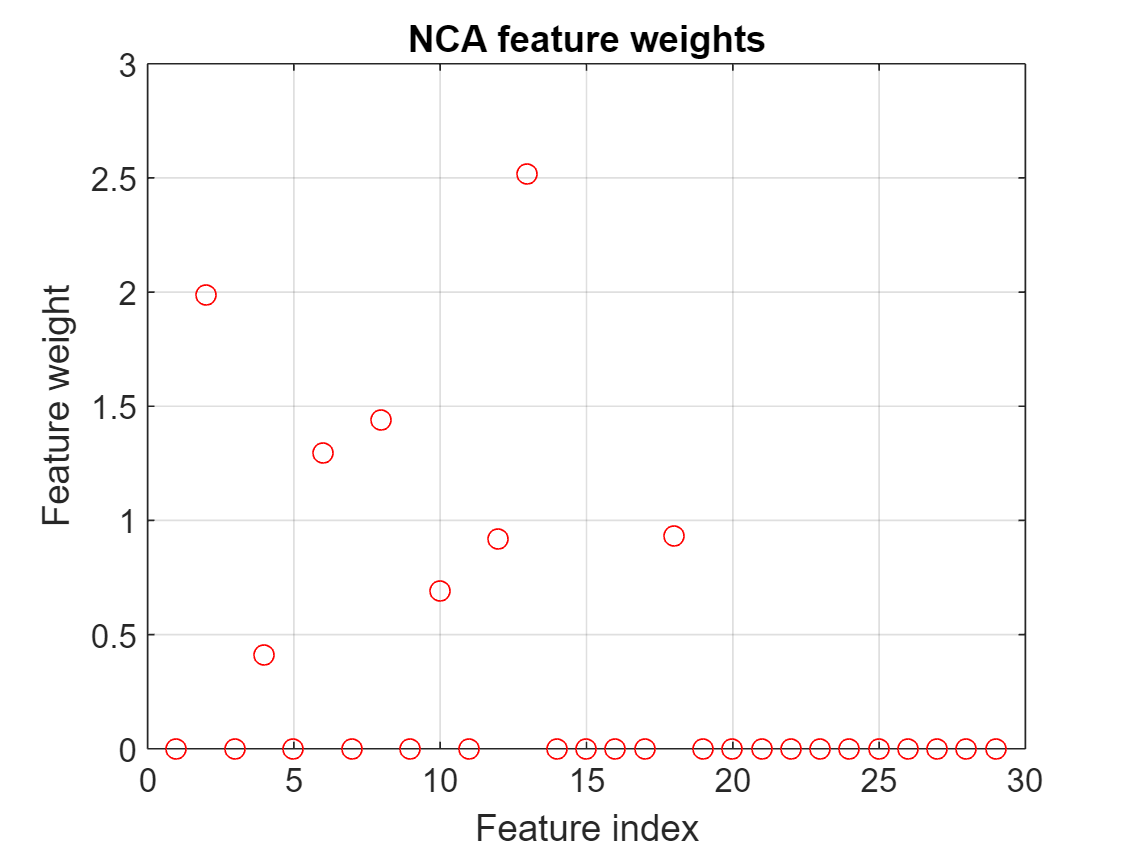

figure()
plot(nca.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')
title('NCA feature weights')


figure
fitted = predict(nca, Xe)

fitted =     0.1609
    0.0876
    0.0772
    0.0735
    0.0722
    0.0716
    0.0714
    0.0732
    0.0700
    0.0702


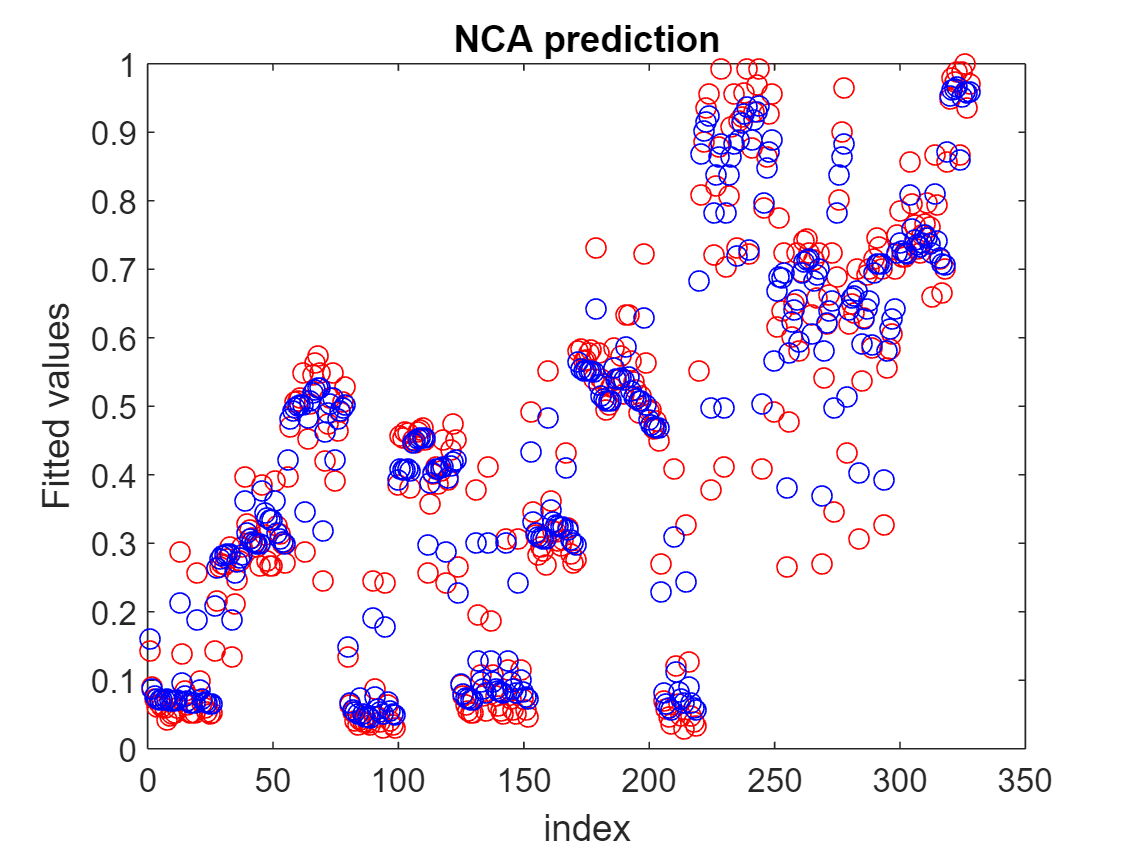

plot(Ye,'ro')
hold on
plot(fitted,'bo')
xlabel('index')
ylabel('Fitted values')
title('NCA prediction')

regression is too strong? 

try different loss functions and test against random weights ->not big impact with L =1/n

% check the other funcion
nca = fsrnca(Xe, Ye, 'Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  1.805313e-01 |   7.983e-03 |   0.000e+00 |        |   7.516e+01 |   0.000e+00 |   YES  |
|        1 |  1.395318e-01 |   1.772e-02 |   2.208e+00 |    OK  |   4.044e+01 |   1.000e+00 |   YES  |
|        2 |  1.339777e-01 |   1.053e-02 |   2.236e+00 |    OK  |   3.232e+01 |   1.000e+00 |   YES  |
|        3 |  1.272269e-01 |   6.884e-03 |   5.519e-01 |    OK  |   4.648e+01 |   1.000e+00 |   YES  |
|        4 |  1.234164e-01 |   1.086e-02 |   7.635e-01 |    OK  |   2.369e+01 |   5.000e-01 |   YES  |
|        5 |  1.213879e-01 |   3.126e-03 |   3.941e-01 |    OK  |   1.749e+01 |   1.000e+00 |   YES  

nca =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods



% rand_weights= rand(size(Xe,2),1)
% default regularization
% nca_rand= fsrnca(Xe, Ye, 'InitialFeatureWeights',rand_weights,'Verbose',2)

% from mad= 0.0288; mse= 0.0015just squared, take absolute error 

% lossNCAMSERAND = loss(nca_rand,Xtest,Ytest,'LossFunction','mse');  
% 
% lossNCAMADRAND = loss(nca_rand,Xtest,Ytest,'LossFunction','mad');  

%just the sqrt, keep MAD
lossNCAMSE = loss(nca,Xe,Ye,'LossFunction','mse')  

lossNCAMSE = 0.0015

lossNCAMAD = loss(nca,Xe,Ye,'LossFunction','mad')  

lossNCAMAD = 0.0293

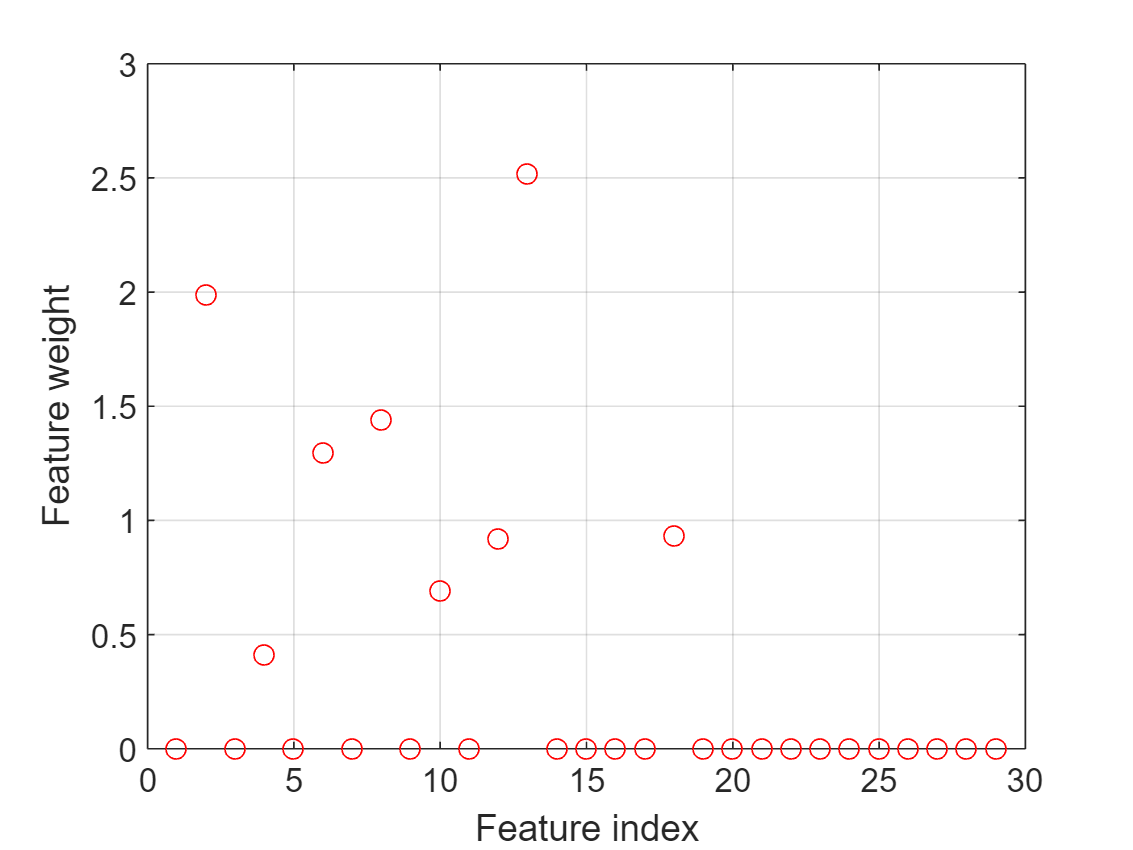

figure()
plot(nca.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')

nca_none = fsrnca(Xe, Ye,'FitMethod', 'none', 'Verbose',2)

nca_none =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'none'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: []
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


loss_none = loss(nca_none,Xe,Ye,'LossFunction','mad') 

loss_none = 0.0531


nca_avg= fsrnca(Xe, Ye, 'FitMethod', 'average','LossFunction','mad')

nca_avg =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'average'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 0
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×10 double]
                  FitInfo: [10×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


loss_avg = loss(nca_avg,Xe,Ye,'LossFunction','mad') 

loss_avg = 0.0703

(LBFGS)EXACT MAD: 0.0303    NONE :0.053      AVG : 0.0681

(SGD) exact : 0.0291, minibatch_lbfgs: 0.0293

 nca_sgd = fsrnca(Xe, Ye,'FitMethod', 'exact','solver','lbfgs','Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  1.805313e-01 |   7.983e-03 |   0.000e+00 |        |   7.516e+01 |   0.000e+00 |   YES  |
|        1 |  1.395318e-01 |   1.772e-02 |   2.208e+00 |    OK  |   4.044e+01 |   1.000e+00 |   YES  |
|        2 |  1.339777e-01 |   1.053e-02 |   2.236e+00 |    OK  |   3.232e+01 |   1.000e+00 |   YES  |
|        3 |  1.272269e-01 |   6.884e-03 |   5.519e-01 |    OK  |   4.648e+01 |   1.000e+00 |   YES  |
|        4 |  1.234164e-01 |   1.086e-02 |   7.635e-01 |    OK  |   2.369e+01 |   5.000e-01 |   YES  |
|        5 |  1.213879e-01 |   3.126e-03 |   3.941e-01 |    OK  |   1.749e+01 |   1.000e+00 |   YES  

nca_sgd =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


 loss_sgd = loss(nca_sgd,Xe,Ye,'LossFunction','mad') 

loss_sgd = 0.0293


nca_minibatch = fsrnca(Xe, Ye,'FitMethod', 'exact','solver','minibatch-lbfgs','Verbose',2)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.853160e-01 |   2.000000e-01 |
|            2 |  1.836925e-01 |   4.000000e-01 |
|            3 |  1.805589e-01 |   8.000000e-01 |
|            4 |  1.748795e-01 |   1.600000e+00 |
|            5 |  1.650697e-01 |   3.200000e+00 |
|            6 |  1.513223e-01 |   6.400000e+00 |
|            7 |  1.375784e-01 |   1.280000e+01 |
|            8 |  1.301633e-01 |   2.560000e+01 |
|            9 |  1.301633e-01 |   2.560000e+01 |
|           10 |  1.301633e-01 |   2.560000e+01 |
|           11 |  1.301633e-01 |   2.560000e+01 |
|           12 |  1.301633e-01 |   2.560000e+01 |
|           13 |  1.301633e-01 |   2.560000e+01 |
|           14 |  1.301633e-01 |   2.560000e+01 |
|           15 |

nca_minibatch =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'minibatch-lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


loss_mb = loss(nca_minibatch,Xe,Ye,'LossFunction','mad')

loss_mb = 0.0302

% 'lbfgs' | 'sgd' | 'minibatch-lbfgs'

% not stratisfied
c = cvpartition(size(Xe, 1),'Holdout',0.25)

c = Hold-out cross validation partition
   NumObservations: 328
       NumTestSets: 1
         TrainSize: 246
          TestSize: 82

idxTrain = training(c)

idxTrain = 328×1 logical array
   1
   0
   1
   1
   0
   1
   1
   1
   1
   1


x_train = Xe(idxTrain,:);
y_train = Ye(idxTrain,1)

y_train =     0.1434
    0.0738
    0.0621
    0.0616
    0.0597
    0.0431
    0.0492
    0.0522
    0.0597
    0.2874


idxNew = test(c)

idxNew = 328×1 logical array
   0
   1
   0
   0
   1
   0
   0
   0
   0
   0


x_test = Xe(idxNew,:);
y_test = Ye(idxNew,1);

nca_test = fsrnca(x_train,y_train ,'FitMethod', 'exact','solver','sgd','Verbose',2)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  2.001110e-01 |   2.000000e-01 |
|            2 |  1.974418e-01 |   4.000000e-01 |
|            3 |  1.924171e-01 |   8.000000e-01 |
|            4 |  1.837207e-01 |   1.600000e+00 |
|            5 |  1.701230e-01 |   3.200000e+00 |
|            6 |  1.547188e-01 |   6.400000e+00 |
|            7 |  1.417135e-01 |   1.280000e+01 |
|            8 |  1.381365e-01 |   2.560000e+01 |
|            9 |  1.381365e-01 |   2.560000e+01 |
|           10 |  1.381365e-01 |   2.560000e+01 |
|           11 |  1.381365e-01 |   2.560000e+01 |
|           12 |  1.381365e-01 |   2.560000e+01 |
|           13 |  1.381365e-01 |   2.560000e+01 |
|           14 |  1.381365e-01 |   2.560000e+01 |
|           15 |

nca_test =   FeatureSelectionNCARegression
          NumObservations: 246
          ModelParameters: [1×1 struct]
                   Lambda: 0.0041
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [246×29 double]
                        Y: [246×1 double]
                        W: [246×1 double]


  Properties, Methods


loss_sgd = loss(nca_test,x_test,y_test,'LossFunction','mad')

loss_sgd = 0.0596

nca_test = fsrnca(x_train,y_train ,'FitMethod', 'exact','Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  2.118684e-01 |   8.750e-03 |   0.000e+00 |        |   6.857e+01 |   0.000e+00 |   YES  |
|        1 |  1.652081e-01 |   4.033e-02 |   2.627e+00 |    OK  |   1.922e+01 |   1.000e+00 |   YES  |
|        2 |  1.425841e-01 |   8.407e-03 |   1.575e+00 |    OK  |   1.165e+01 |   1.000e+00 |   YES  |
|        3 |  1.409135e-01 |   7.194e-03 |   3.035e-01 |    OK  |   6.950e+01 |   1.000e+00 |   YES  |
|        4 |  1.384181e-01 |   2.612e-03 |   7.771e-01 |    OK  |   6.136e+01 |   1.000e+00 |   YES  |
|        5 |  1.378181e-01 |   1.194e-03 |   2.300e-01 |    OK  |   3.032e+01 |   1.000e+00 |   YES  

nca_test =   FeatureSelectionNCARegression
          NumObservations: 246
          ModelParameters: [1×1 struct]
                   Lambda: 0.0041
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [246×29 double]
                        Y: [246×1 double]
                        W: [246×1 double]


  Properties, Methods


loss_lbg = loss(nca_test,x_test,y_test,'LossFunction','mad')

loss_lbg = 0.0582

loss lbg = 0.0482, sgd =0.0505

cv        = cvpartition(Ye,'kfold',5);

numtestsets   = cv.NumTestSets;
lambdavalues  = linspace(0,1,20)/length(Ye); 
lossvalues    = zeros(length(lambdavalues),numtestsets);


n = 328; 
mape = @(y, yp) (abs(y - yp) ./y  )* 100/n

mape = function_handle with value:
    @(y,yp)(abs(y-yp)./y)*100/n



for i = 1:length(lambdavalues)                
    for k = 1:numtestsets
        
        % Extract the training set from the partition object
        Xtrain = Xe(cv.training(k),:);
        Ytrain = Ye(cv.training(k),:);
        
        % Extract the test set from the partition object
        Xtest = Xe(cv.test(k),:);
        Ytest = Ye(cv.test(k),:);
        
        % Train an nca model for classification using the training set
        ncaMdl = fsrnca(Xtrain,Ytrain,'FitMethod','exact','Standardize',true, ...
            'Solver','sgd','Lambda',lambdavalues(i) );
        
        % Compute the classification loss for the test set using the nca
        % model
        lossvalues(i,k) = loss(ncaMdl, Xtest, Ytest,'LossFunction','mad');   
   
    end                          
end

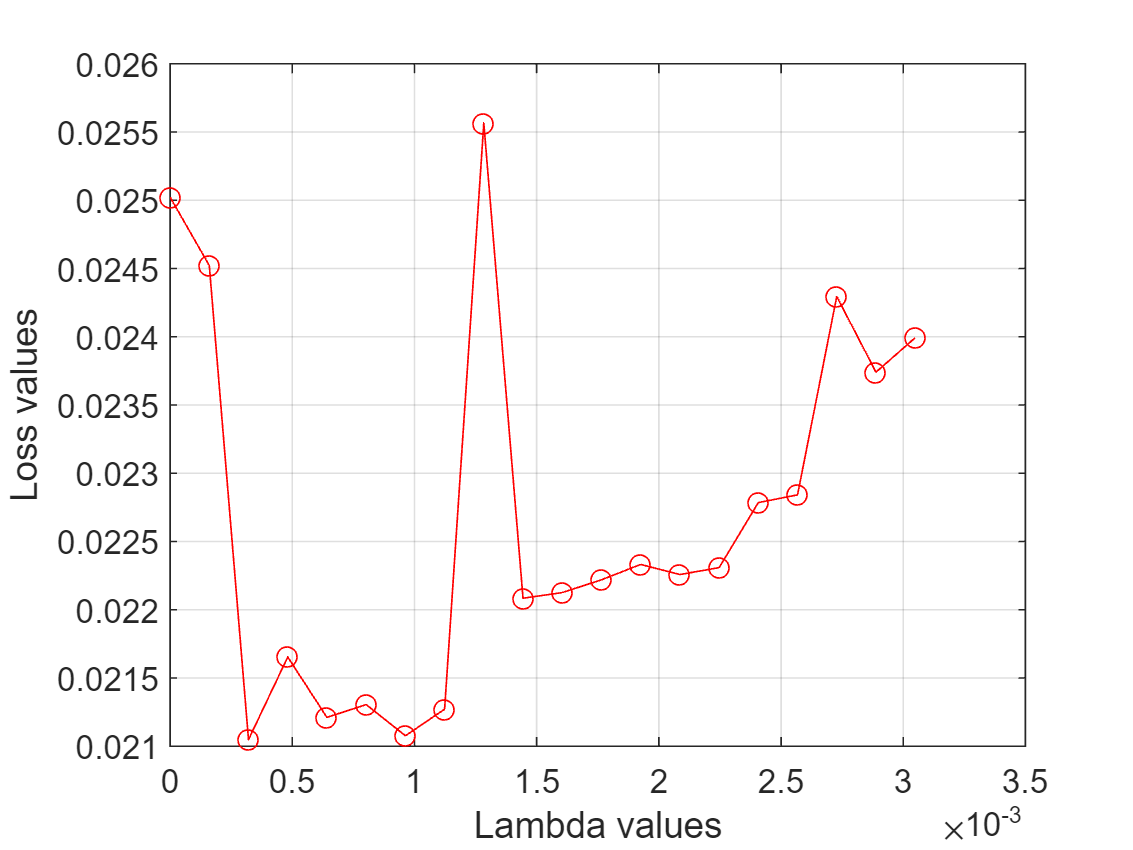

figure
plot(lambdavalues,mean(lossvalues,2),'ro-')
xlabel('Lambda values')
ylabel('Loss values')
grid on

lamba should be super small

same trend upwards in loss once l <0.00 (in scale 10 ^-3), find best lamdba 

[~,idx] = min(mean(lossvalues,2)); % Find the index
bestlambda = lambdavalues(idx) % Find the best lambda value

bestlambda = 3.2092e-04

ncaBest = fsrnca(Xtrain, Ytrain, 'FitMethod','exact','Verbose',1, ...
     'Solver','sgd','Lambda',bestlambda);


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.016893e-01 |   2.000000e-01 |
|            2 |  1.010996e-01 |   4.000000e-01 |
|            3 |  9.993862e-02 |   8.000000e-01 |
|            4 |  9.762062e-02 |   1.600000e+00 |
|            5 |  9.261707e-02 |   3.200000e+00 |
|            6 |  8.172960e-02 |   6.400000e+00 |
|            7 |  6.364656e-02 |   1.280000e+01 |
|            8 |  5.343534e-02 |   2.560000e+01 |
|            9 |  5.248088e-02 |   5.120000e+01 |
|           10 |  5.248088e-02 |   5.120000e+01 |
|           11 |  5.248088e-02 |   5.120000e+01 |
|           12 |  5.136099e-02 |   1.024000e+02 |
|           13 |  5.136099e-02 |   1.024000e+02 |
|           14 |  5.102536e-02 |   5.120000e+01 |
|           15 |

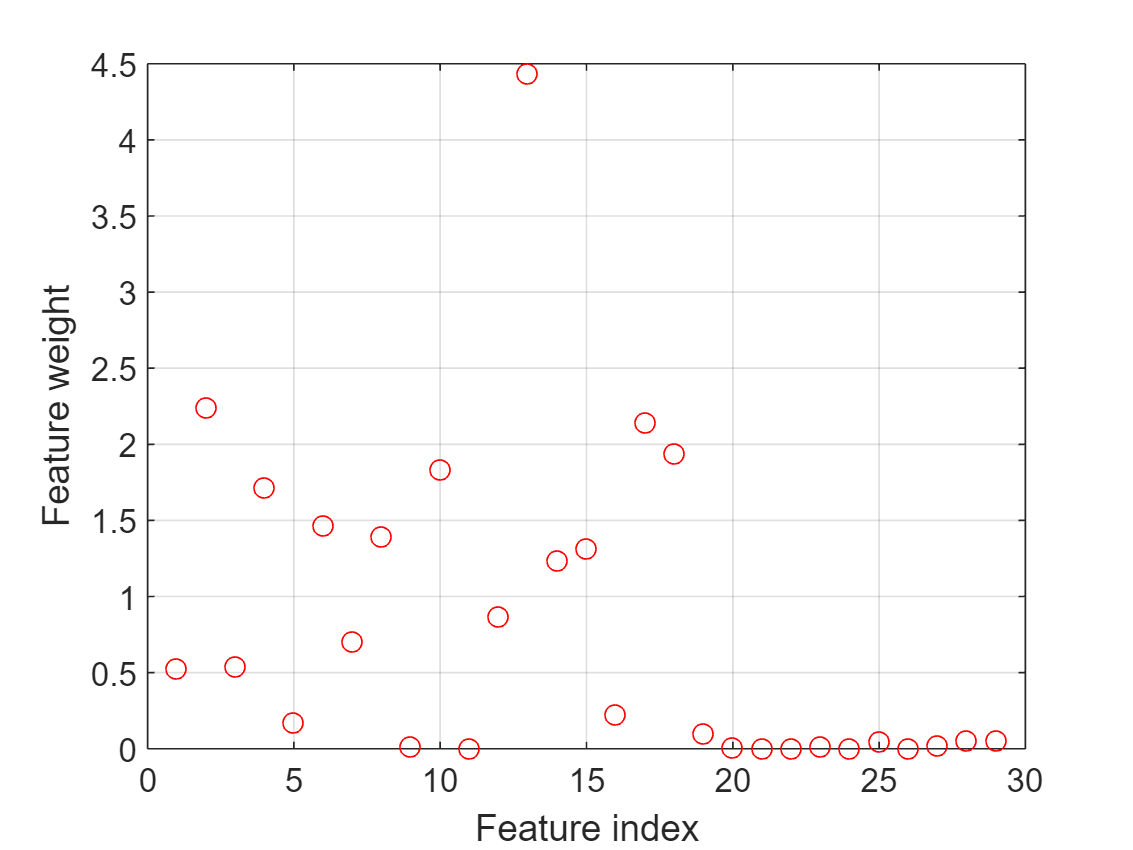

figure()
plot(ncaBest.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')

#### testing the embedded NCA

fitted = predict(ncaBest, Xtest)

fitted =     0.0655
    0.0494
    0.1604
    0.1454
    0.2896
    0.3908
    0.3045
    0.2733
    0.2877
    0.5034


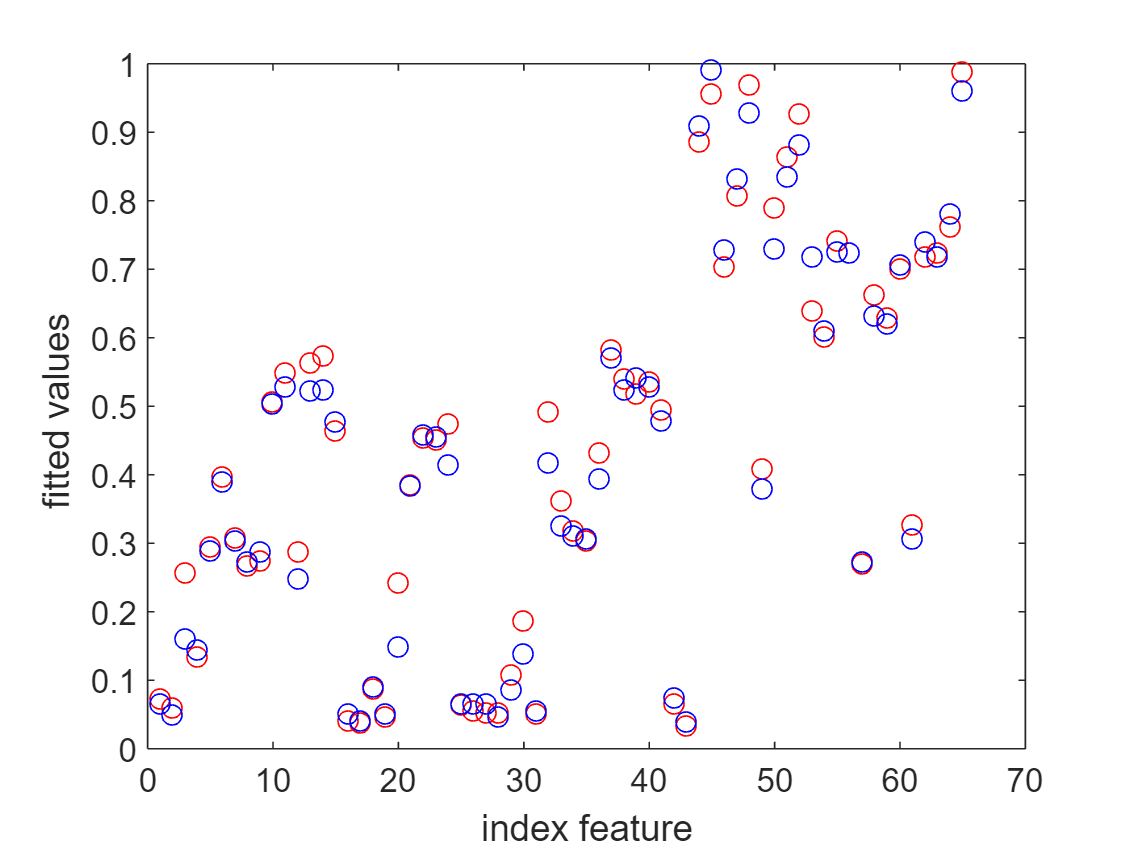

plot(Ytest, 'ro')
hold on 
plot(fitted, 'bo')
xlabel('index feature')
ylabel('fitted values ')

lossvalue = loss(ncaBest, Xtest, Ytest,'LossFunction','mad')

lossvalue = 0.0220

weights = ncaBest.FeatureWeights

weights =     0.5274
    2.2390
    0.5382
    1.7186
    0.1694
    1.4687
    0.7059
    1.3924
    0.0149
    1.8323


[weightsScores, weightsIndices] = sort(weights, 'descend')

weightsScores =     4.4345
    2.2390
    2.1422
    1.9385
    1.8323
    1.7186
    1.4687
    1.3924
    1.3126
    1.2397


weightsIndices =     13
     2
    17
    18
    10
     4
     6
     8
    15
    14


% only taking 10 best features
fsNCA = lablesE(1,weightsIndices(1:10))

fsNCA = 1×10 table
         lables13                 lables2                lables23               lables28                  lables10             lables4              lables6                      lables8                 lables18        lables14  
    __________________    ________________________    ______________    _________________________    ___________________    ______________    ____________________    _____________________________    _____________    ___________

    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'impurityXc'}    {'MajorityPolymer_HDPE1'}    {'Contaminant_SCB'}    {'Matrix_SCB'}    {'Matrix_viscosity'}    {'Contaminant_crys


%  no threshold needed, take just only 10 best 
% idxNCA = zeros(length(weights),1)
% counter= 1;
% for i= 1: length(weights)
%     if weights(i) > 1
%         idxNCA(counter, 1) = 
%         counter = counter + 1; 
%     end
% end
% idxNCA = idxNCA(idxNCA~= 0)

#### F-test

[idx,scores] = fsrftest(Xe,Ye);
% the values in scores are the negative logs of the p-values
find(isinf(scores)) 


ans =

  1×0 empty double row vector



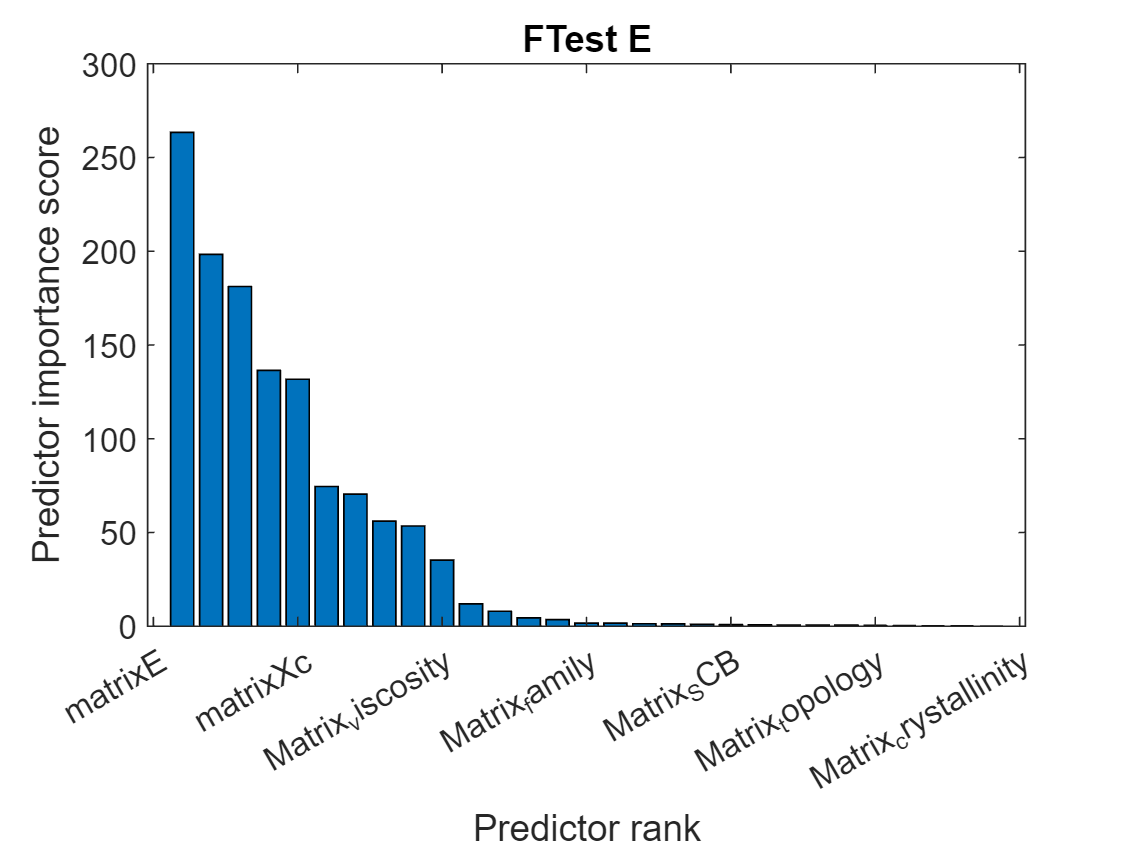

% no neg pvalues, meaning null hypothesis??
figure;
bar(scores(idx))
xticks('auto')
xticklabels(table2cell(lablesE(1,idx)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest E')


fsFTEST = lablesE(1,idx(1:10));
relevant_features_ftest = E(:,idx);
% scrs = sorted(scores, 'descend')
% figure; 
% plot(scores(idx),relevant_features_names)
% xlabel('Predictor rank')
% ylabel('Predictor importance score')


scatter3(relevant_features_ftest(:,1),relevant_features_ftest(:,2) ,Ye)
corr(relevant_features_ftest(:,1), Ye)

ans = 0.9204

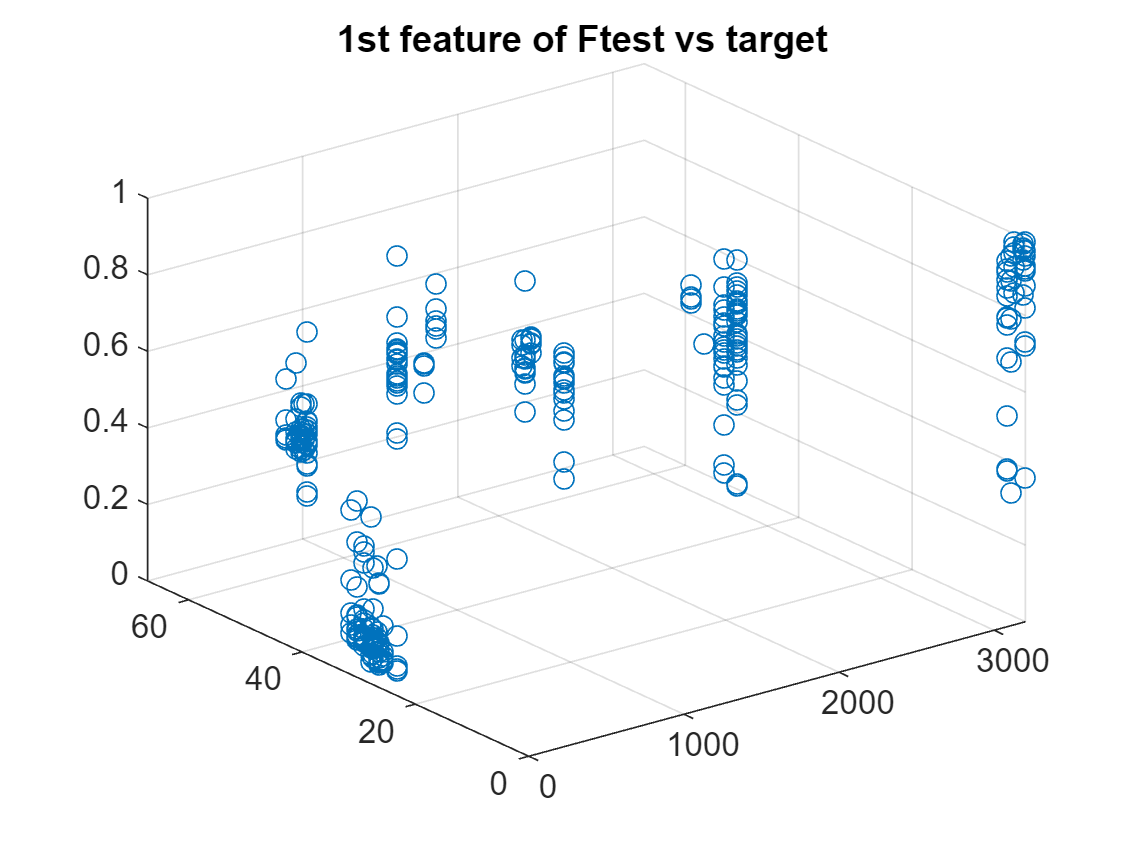

title('1st feature of Ftest vs target ')

#### Spearman's correlation

%spearman correlation in whole datset
sc=spearman_corr_n_best(Xe, Ye, 10)

sc_n =     14
     4
     1
     3
     6
    19
    20
    16
     5
    21


sc =     14
     4
     1
     3
     6
    19
    20
    16
     5
    21


fsSC = lablesE(1,sc)

fsSC = 1×10 table
     lables14         lables4             lables1               lables3                lables6                   lables29                      lables30               lables22         lables5               lables31        
    ___________    ______________    _________________    ___________________    ____________________    _________________________    __________________________    ____________    ______________    _______________________

    {'matrixE'}    {'Matrix_SCB'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'matrixXc'}    {'Matrix_LCB'}   

#### MRMR

[idxmrmr, scoresmrmr] = fsrmrmr(Xe,Ye);
figure()
bar(scoresmrmr(idxmrmr))

fsMRMR = lablesE(1,idxmrmr(1:10))

fsMRMR = 1×10 table
     lables14           lables13                lables37                    lables29                lables4               lables35                 lables1                 lables2                   lables3                  lables28         
    ___________    __________________    _______________________    _________________________    ______________    _______________________    _________________    ________________________    ___________________    _________________________

    {'matrixE'}    {'WeightImpurity'}    {'MajorityPolymer_PS2'}    {'MajorityPolymer_LDPE1'}    {'Matrix_SCB'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}

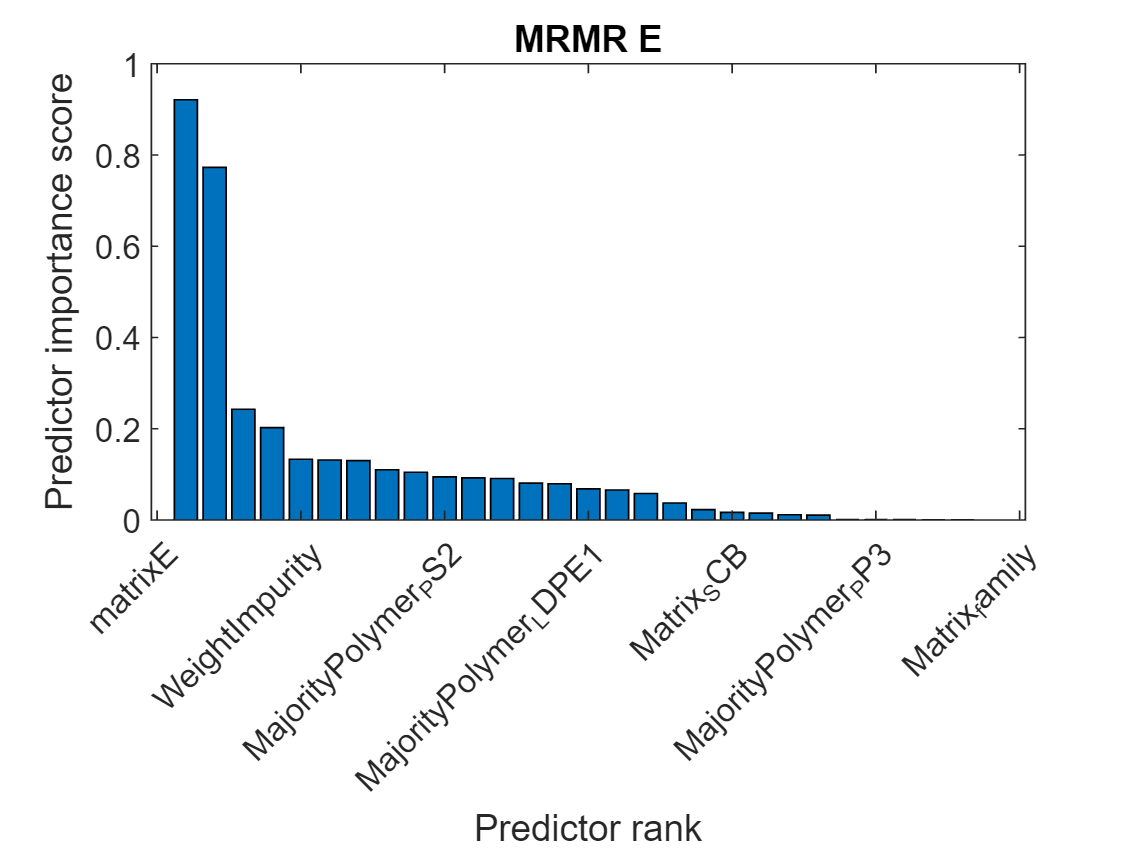

xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR E')
% predictorNames = cartable.Properties.VariableNames(1:end-1);
% xticklabels(strrep(rankF_mrmr,"_","\_"))
xticklabels(table2cell(fsMRMR))
xtickangle(45) 

FOR NCA AND MRMR MAJORITY LDPE IS AN IMPORTANT FETAURE

#### ensembeling an array with all results given results of NCA MRMR FTEST SPEARCORR RFPER

for simplicicty keep always this order 

%adding permutation imprtance
rf_idx = table2array(PER(2,:))

rf_idx =     13    12    14    15    16     9     1    25     6    35


fsPER = lablesE(1,rf_idx)

fsPER = 1×10 table
         lables13                 lables12              lables14        lables18         lables22              lables9                  lables1                lables35                  lables6                  lables45        
    __________________    _________________________    ___________    _____________    ____________    ________________________    _________________    _______________________    ____________________    _______________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE'}    {'impurityE'}    {'matrixXc'}    {'Contaminant_topology'}    {'Matrix_family'}    {'MajorityPolymer_PP3'}    {'Matri

features= [table2array(fsNCA), table2array(fsMRMR),table2array(fsFTEST), table2array(fsSC) , table2array(fsPER)]

features = 1×50 cell array
    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'impurityXc'}    {'MajorityPolymer_HDPE1'}    {'Contaminant_SCB'}    {'Matrix_SCB'}    {'Matrix_viscosity'}    {'Contaminant_crystallinity'}    {'impurityE'}    {'matrixE'}    {'matrixE'}    {'WeightImpurity'}    {'MajorityPolymer_PS2'}    {'MajorityPolymer_LDPE1'}    {'Matrix_SCB'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'MajorityPolymer_HDPE1'}    {'matrixE'}    {'matrixXc'}    {'Matrix_viscosity'}    {'Matrix_family'}    {'Matrix_SCB'}    {'Matrix_topology'}    {'Matrix_crystallinity'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'}    {'matrixE'}    {'Matrix_SCB'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'matrixXc'}    {'Matrix_LCB'}    {'MajorityPolymer_PA1'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE


%USING BORDA COUNT 
% Find unique strings
%uniqueF= unique(features);
% 
% % Initialize an array to store the weighted occurrences
% weightedOccurrences = zeros(size(uniqueF));
% 
% % Calculate weighted occurrences based on position
% for i = 1:numel(features)
%     % + (11- mod(i, 10))
%     stringIndex = find(strcmp(uniqueF, features{i})); % Find the index of the string
%     weightedOccurrences(stringIndex) = weightedOccurrences(stringIndex) + + (11- mod(i, 10)); % Assign weight based on position ORIGINAL POSITION, GIVEN IT GOES BY 10S MOD - 11
% end
% figure()
% % Plot the weighted frequency of occurrence
% bar(1:numel(uniqueF), weightedOccurrences)
% xticks(1:numel(uniqueF))
% xticklabels(uniqueF)
% title('Sum of ranking per Feature WHOLE')
% xlabel('features ')
% ylabel('Total sum rank')

### TRYING WITH SMALLER DATASETS

they have 1HE and the other features! so reduce!! 

#### POLY AND NON POLYEFINE only elasticity

Do exactly the same metholody before but applying all techniques to both partitions, the general feature array for both partitions will have the same order as before. 

P = readtable('data_reduced_p.csv');
 % cannot becasuse 1hor encondings give inf 
% P = normalize(P)
NP = readtable('data_reduced_np.csv');

% because of ârtition the first col(matrix family) will not be relevant 
P =  table2array(P(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

P = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  

NP = table2array(NP(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

NP = 1.0e+03 *

    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0005    3.0839    0.9845         0    0.0660    1.7811         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0002    3.0839    0.9845         0    0.0660    2.6098         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0001    3.0839    0.9845         0    0.0660    2.8575         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020 


% separate cols and norm
x_p= [P(:,1:17), P(:,19:end)];
y_p = P(:,18)/max(E(:,18));
x_np= [NP(:,1:17), NP(:,19:end)];
y_np = NP(:,18)/max(E(:,18));
cc_p = x_p(:,14:17) ./ max(x_p(:,14:17));   x_p(:,14:17)= cc_p

x_p =          0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.1087    0.2976    0.4860    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.1087    0.2976    0.4860    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.1087    0.2976    0.4860    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000 

cc_np = x_np(:,14:17) ./ max(x_np(:,14:17));    x_np(:,14:17)= cc_np

x_np =     1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.9631    0.3087         0    0.9812         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.9631    0.3087         0    0.9812         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.9631    0.3087         0    0.9812         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000

% fast splitting 10% of data ->32.8 instances 
[rP, cP ]=size(x_p)

rP = 219

cP = 29

PD = 0.90 ;
idx = randperm(rP);
XPtrain = x_p(idx(1:round(rP*PD)),:);
XPtest = x_p(idx(round(rP*PD)+1:end),:);
YPtrain = y_p(idx(1:round(rP*PD)),:);
YPtest = y_p(idx(round(rP*PD)+1:end),:);

[rNP, cNP ]=size(x_np)

rNP = 109

cNP = 29

idx = randperm(rNP);
XNPtrain = x_np(idx(1:round(rNP*PD)),:);
XNPtest = x_np(idx(round(rNP*PD)+1:end),:);
YNPtrain = y_np(idx(1:round(rNP*PD)),:);
YNPtest = y_np(idx(round(rNP*PD)+1:end),:);
% fitmethod : exact

nca_p = fsrnca(x_p, y_p, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  6.381899e-02 |   2.000000e-01 |
|            2 |  6.224384e-02 |   4.000000e-01 |
|            3 |  5.970487e-02 |   8.000000e-01 |
|            4 |  5.609172e-02 |   1.600000e+00 |
|            5 |  5.178702e-02 |   3.200000e+00 |
|            6 |  4.010636e-02 |   6.400000e+00 |
|            7 |  3.428360e-02 |   1.280000e+01 |
|            8 |  3.206608e-02 |   2.560000e+01 |
|            9 |  3.206608e-02 |   2.560000e+01 |
|           10 |  3.206608e-02 |   2.560000e+01 |
|           11 |  3.206608e-02 |   2.560000e+01 |
|           12 |  3.206608e-02 |   2.560000e+01 |
|           13 |  3.206608e-02 |   2.560000e+01 |
|           14 |  3.206608e-02 |   2.560000e+01 |
|           15 |

nca_p =   FeatureSelectionNCARegression
          NumObservations: 219
          ModelParameters: [1×1 struct]
                   Lambda: 3.2092e-04
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: [29×1 double]
                    Sigma: [29×1 double]
                        X: [219×29 double]
                        Y: [219×1 double]
                        W: [219×1 double]


  Properties, Methods


nca_np = fsrnca(x_np, y_np, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  9.433260e-02 |   2.000000e-01 |
|            2 |  8.784064e-02 |   4.000000e-01 |
|            3 |  7.613609e-02 |   8.000000e-01 |
|            4 |  6.388942e-02 |   1.600000e+00 |
|            5 |  5.643463e-02 |   3.200000e+00 |
|            6 |  5.427361e-02 |   6.400000e+00 |
|            7 |  4.972353e-02 |   1.280000e+01 |
|            8 |  4.972353e-02 |   1.280000e+01 |
|            9 |  4.972353e-02 |   1.280000e+01 |
|           10 |  4.690804e-02 |   2.560000e+01 |
|           11 |  4.690804e-02 |   2.560000e+01 |
|           12 |  4.690804e-02 |   2.560000e+01 |
|           13 |  4.533072e-02 |   5.120000e+01 |
|           14 |  4.533072e-02 |   5.120000e+01 |
|           15 |

nca_np =   FeatureSelectionNCARegression
          NumObservations: 109
          ModelParameters: [1×1 struct]
                   Lambda: 3.2092e-04
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: [29×1 double]
                    Sigma: [29×1 double]
                        X: [109×29 double]
                        Y: [109×1 double]
                        W: [109×1 double]


  Properties, Methods



fittedP= predict(nca_p, XPtrain);
fittedNP= predict(nca_np, XNPtrain);
loss_p = loss(nca_p,XPtest,YPtest,'LossFunction','mad') 

loss_p = 0.0043

loss_np = loss(nca_np,XNPtest,YNPtest,'LossFunction','mad') 

loss_np = 0.0105

 NP = default 3.5283e-04 ; P =4.931e-04

standarizing : NP = 0.0199, P = 0.0219

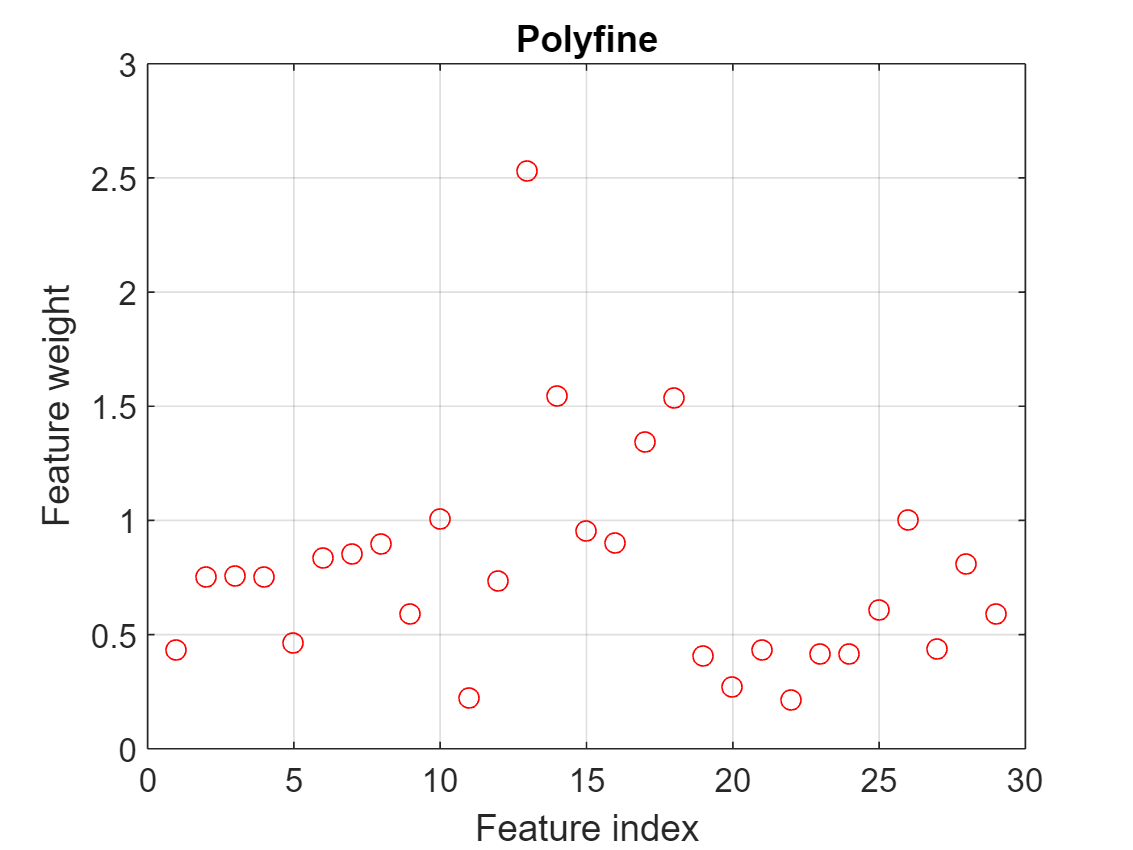

figure()
plot(nca_p.FeatureWeights,'ro')
grid on
%  hold on 
% plot(nca_np.FeatureWeights,'bo')
% hold off
xlabel('Feature index')
ylabel('Feature weight')
title('Polyfine')

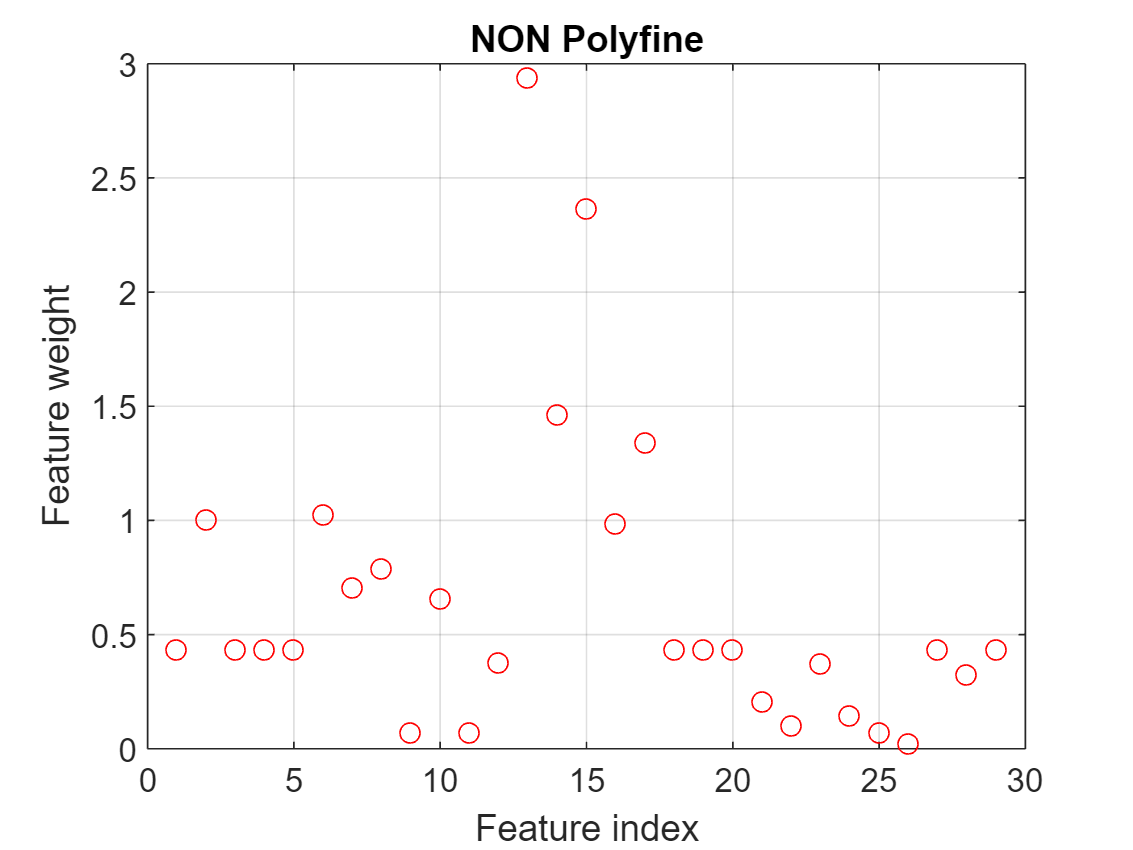


figure()
plot(nca_np.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')
title('NON Polyfine')

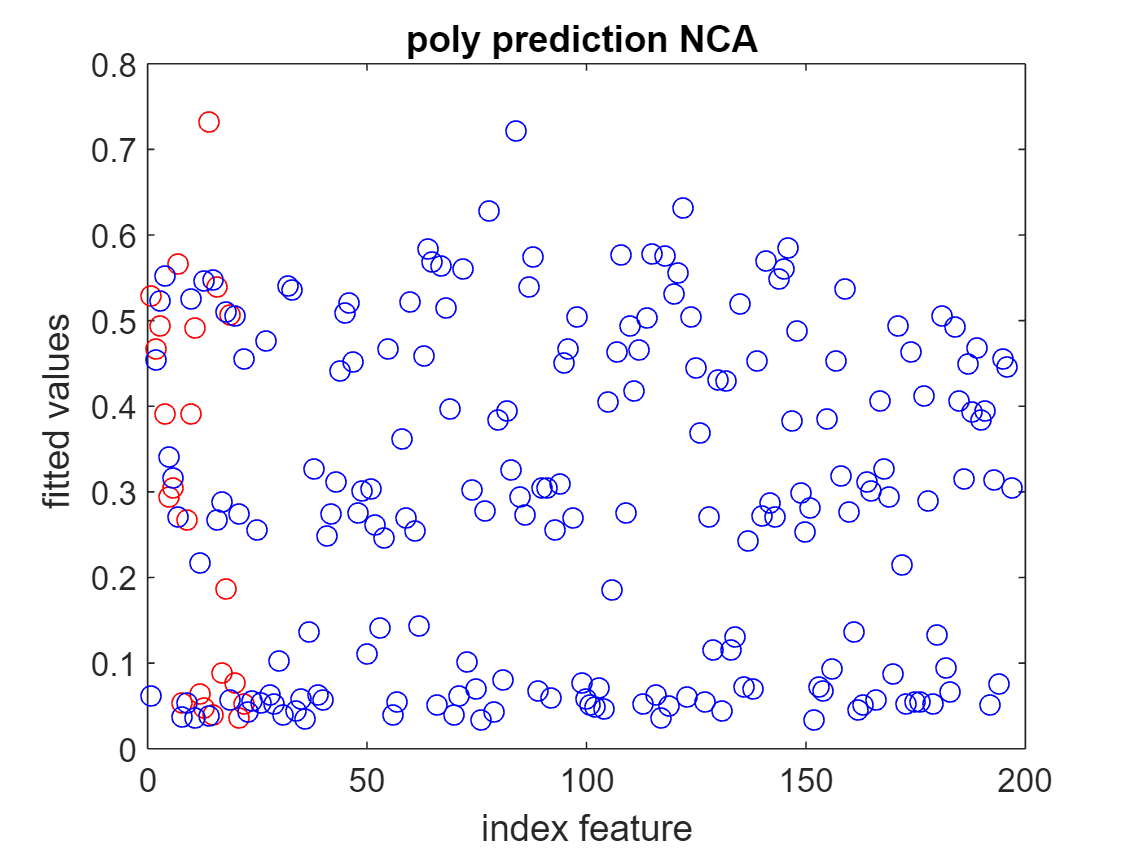


figure()
plot(YPtest, 'ro')
hold on 
plot(fittedP, 'bo')
title('poly prediction NCA ')
xlabel('index feature')
ylabel('fitted values ')

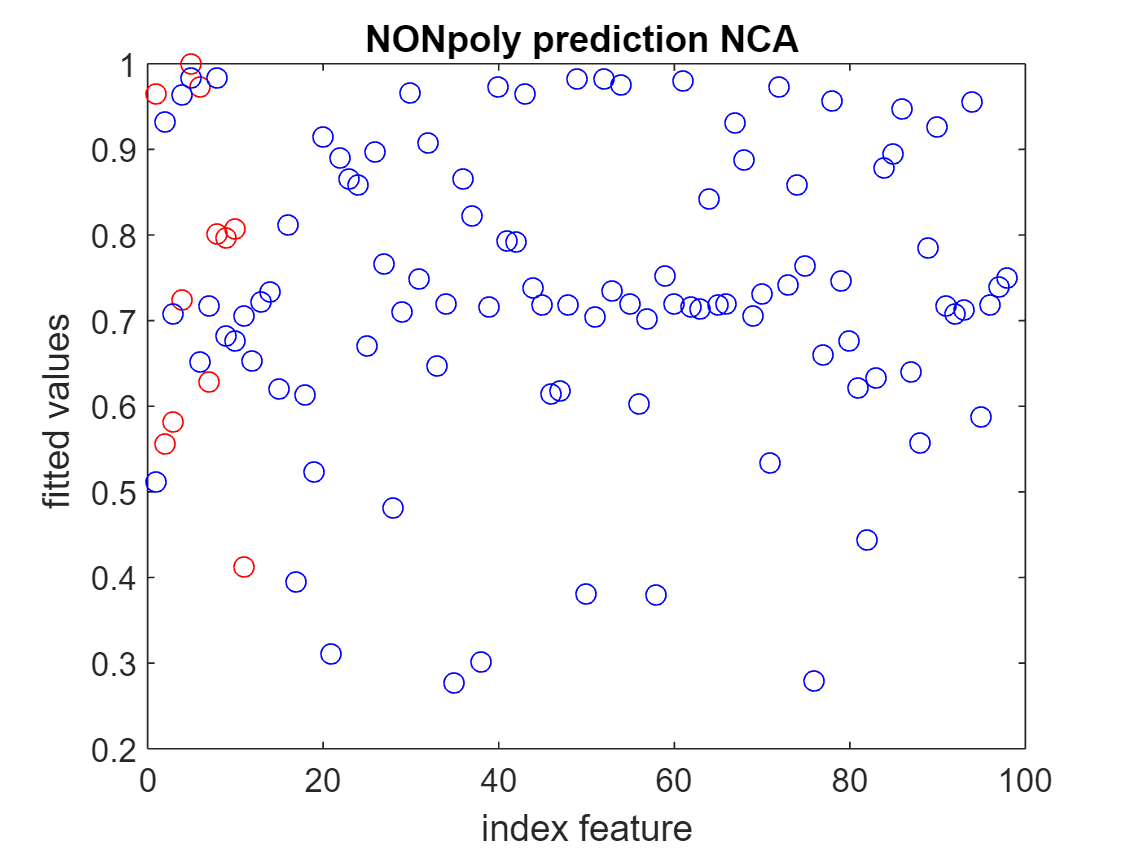


figure()
plot(YNPtest, 'ro')
hold on 
plot(fittedNP, 'bo')
title('NONpoly prediction NCA ')
xlabel('index feature')
ylabel('fitted values ')

weightsP = nca_p.FeatureWeights

weightsP =     0.4361
    0.7559
    0.7586
    0.7559
    0.4655
    0.8391
    0.8562
    0.8999
    0.5921
    1.0068


weightsNP = nca_np.FeatureWeights

weightsNP =     0.4342
    1.0045
    0.4342
    0.4342
    0.4342
    1.0261
    0.7048
    0.7907
    0.0699
    0.6602



[weightsScores, wP] = sort(weightsP, 'descend')

weightsScores =     2.5306
    1.5488
    1.5397
    1.3447
    1.0068
    1.0020
    0.9545
    0.9040
    0.8999
    0.8562


wP =     13
    14
    18
    17
    10
    26
    15
    16
     8
     7


[~, wNP] = sort(weightsNP, 'descend')

wNP =     13
    15
    14
    17
     6
     2
    16
     8
     7
    10


% only taking 10 best features
fsNCA_p = lablesE(1,wP(1:10))

fsNCA_p = 1×10 table
         lables13          lables14              lables28                lables23            lables10                 lables36              lables18         lables22                 lables8                      lables7        
    __________________    ___________    _________________________    ______________    ___________________    _______________________    _____________    ____________    _____________________________    ______________________

    {'WeightImpurity'}    {'matrixE'}    {'MajorityPolymer_HDPE1'}    {'impurityXc'}    {'Contaminant_SCB'}    {'MajorityPolymer_PS1'}    {'impurityE'}    {'matrixXc'}    {'Contaminant

fsNCA_np = lablesE(1,wNP(1:10))

fsNCA_np = 1×10 table
         lables13           lables18        lables14         lables23             lables6                   lables2               lables22                 lables8                      lables7                 lables10      
    __________________    _____________    ___________    ______________    ____________________    ________________________    ____________    _____________________________    ______________________    ___________________

    {'WeightImpurity'}    {'impurityE'}    {'matrixE'}    {'impurityXc'}    {'Matrix_viscosity'}    {'Matrix_crystallinity'}    {'matrixXc'}    {'Contaminant_crystallinity'}    {'Contaminant_

% first col; matrix fam 
[idxP,scoresP] = fsrftest(x_p(:,2:end),y_p);
[idxNP,scoresNP] = fsrftest(x_np(:,2:end) , y_np);
find(isinf(scores)) 


ans =

  1×0 empty double row vector



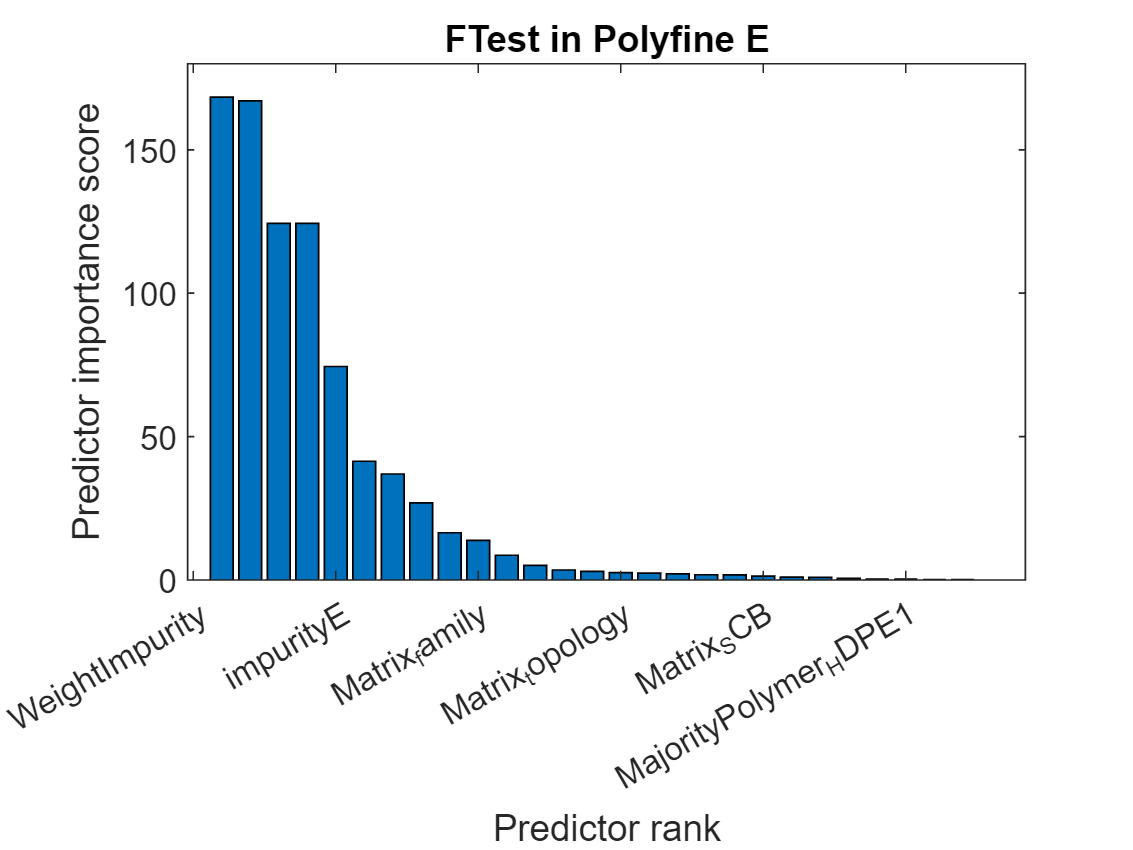

% no neg pvalues, no inf values, test is approppiate 
figure()
bar(scoresP(idxP))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxP)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Polyfine E')

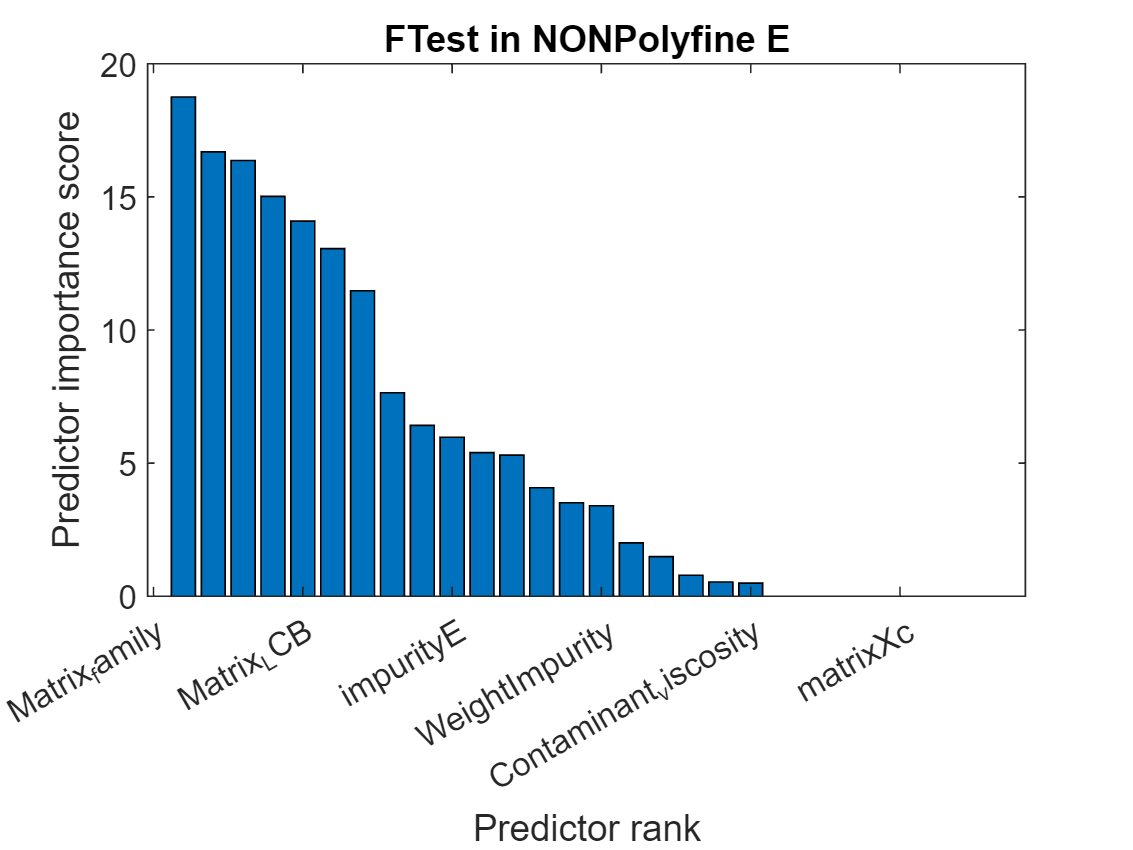


figure()
bar(scoresNP(idxNP))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxNP)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in NONPolyfine E')

fsFTEST_p = lablesE(1,idxP(1:10))

fsFTEST_p = 1×10 table
         lables13           lables18            lables1               lables3             lables4                lables28                lables5                lables29                     lables2              lables14  
    __________________    _____________    _________________    ___________________    ______________    _________________________    ______________    _________________________    ________________________    ___________

    {'WeightImpurity'}    {'impurityE'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'MajorityPolymer_HDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'Matrix_crys

fsFTEST_np = lablesE(1,idxNP(1:10))

fsFTEST_np = 1×10 table
         lables1            lables5          lables18            lables13                 lables12               lables22       lables14              lables9                   lables6                    lables30         
    _________________    ______________    _____________    __________________    _________________________    ____________    ___________    ________________________    ____________________    __________________________

    {'Matrix_family'}    {'Matrix_LCB'}    {'impurityE'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixXc'}    {'matrixE'}    {'Contaminant_topology'}    {'Matrix_viscosity'}   

MRMR is sort of a clustering alg that ranks the features of how well they can 'ressemble' the prediction, 

givne what we saw PCA a clustering technique would not be too off what the prediction as there are three main families adn each run in different ranges by general rule. 


[imrP, scoresP] = fsrmrmr(x_p,y_p);
[imrNP, scoresNP] = fsrmrmr(x_np,y_np);

fsMRMR_p = lablesE(1,imrP(1:10))

fsMRMR_p = 1×10 table
      lables22             lables33                 lables13                lables36               lables4                lables2                     lables28                lables5                 lables30                    lables35        
    ____________    _______________________    __________________    _______________________    ______________    ________________________    _________________________    ______________    __________________________    _______________________

    {'matrixXc'}    {'MajorityPolymer_PP1'}    {'WeightImpurity'}    {'MajorityPolymer_PS1'}    {'Matrix_SCB'}    {'Matrix_crystallinity'}    {'Majorit

fsMRMR_np = lablesE(1,imrNP(1:10))

fsMRMR_np = 1×10 table
          lables6             lables18               lables2                    lables36                   lables7              lables22              lables38                    lables34                    lables32             lables14  
    ____________________    _____________    ________________________    _______________________    ______________________    ____________    _________________________    _______________________    ________________________    ___________

    {'Matrix_viscosity'}    {'impurityE'}    {'Matrix_crystallinity'}    {'MajorityPolymer_PS1'}    {'Contaminant_family'}    {'matrixXc'}    {'MinorityPolymer_

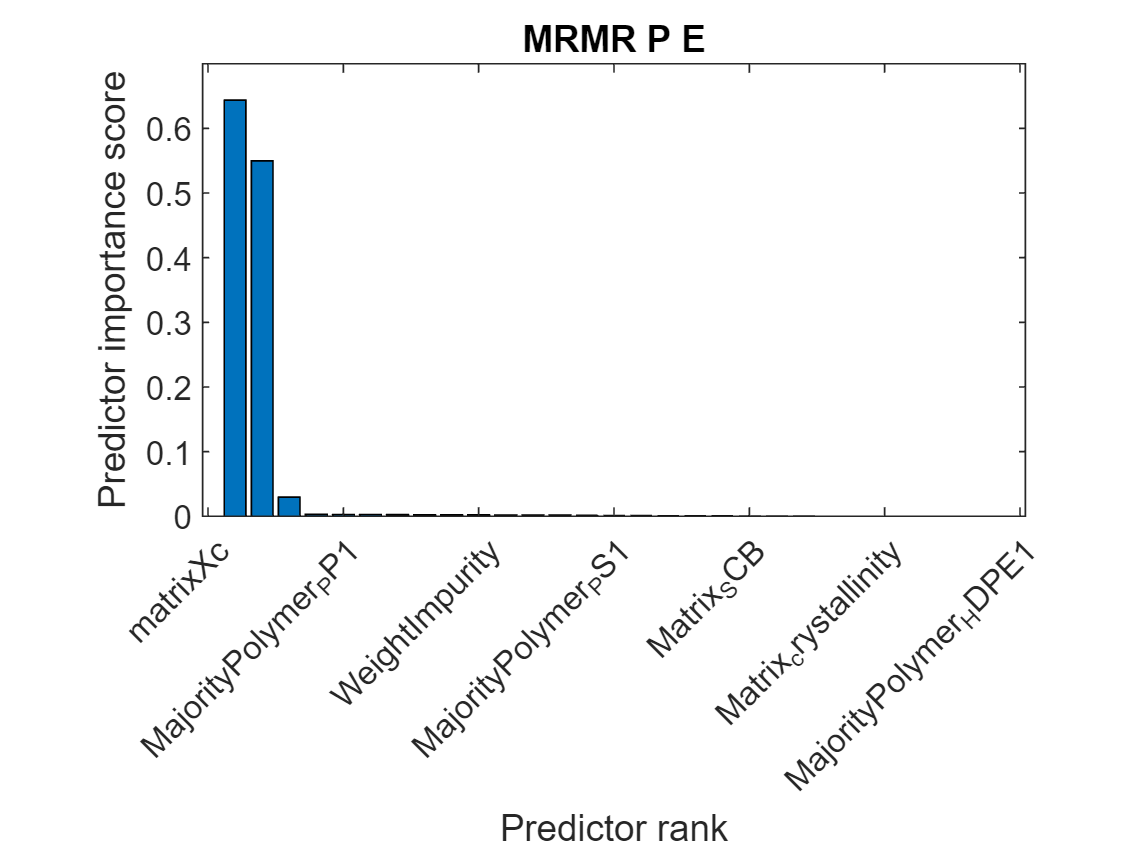


figure()
bar(scoresP(imrP))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR P E')
xticklabels(table2cell(fsMRMR_p))
xtickangle(45)

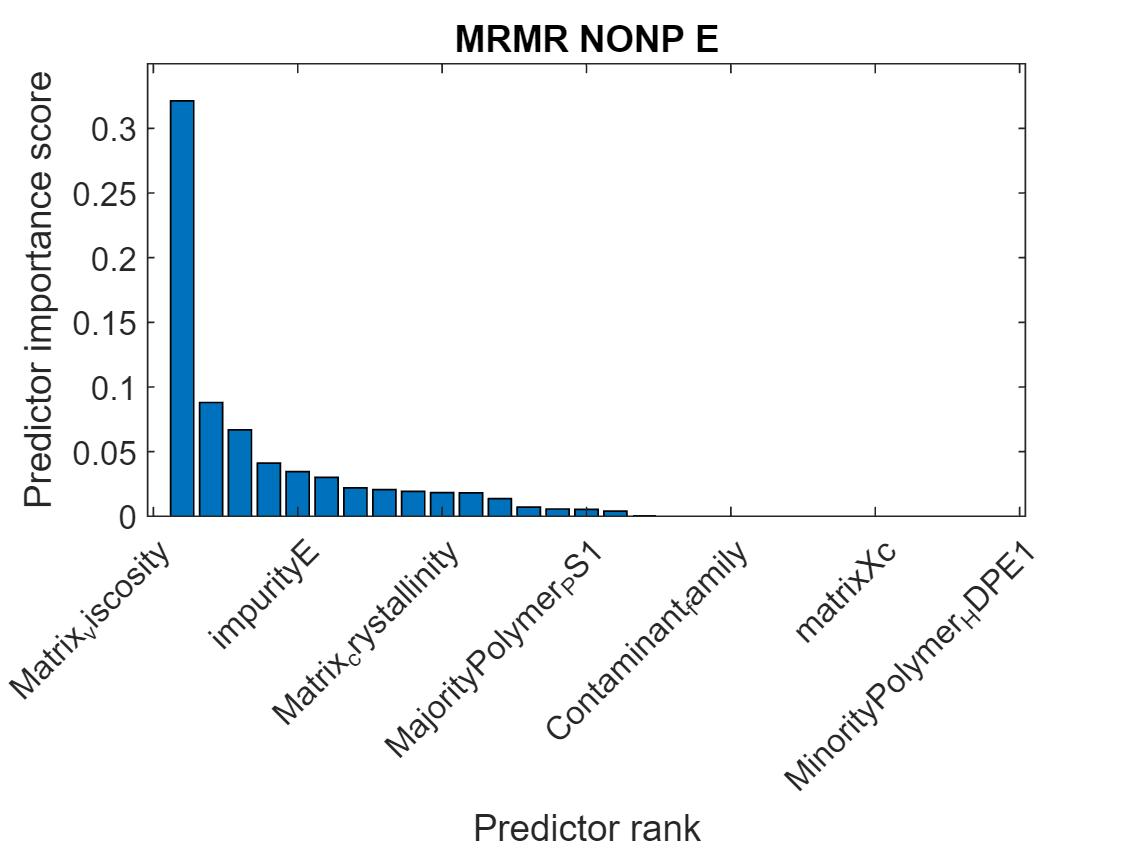


figure()
bar(scoresNP(imrNP))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR NONP E')
xticklabels(table2cell(fsMRMR_np))
xtickangle(45)

sc_p=spearman_corr_n_best(x_p, y_p, 10)

sc_n =      1
    21
    14
     2
     4
    16
    20
    19
     6
     3


sc_p =      1
    21
    14
     2
     4
    16
    20
    19
     6
     3


fsSC_p = lablesE(1,sc_p)

fsSC_p = 1×10 table
         lables1                lables31             lables14              lables2                lables4          lables22               lables30                     lables29                   lables6                 lables3      
    _________________    _______________________    ___________    ________________________    ______________    ____________    __________________________    _________________________    ____________________    ___________________

    {'Matrix_family'}    {'MajorityPolymer_PA1'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'matrixXc'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolyme

sc_np=spearman_corr_n_best(x_np, y_np, 10)

sc_n =      1
     3
     4
     5
    18
    19
    20
    27
    29
     2


sc_np =      1
     3
     4
     5
    18
    19
    20
    27
    29
     2


fsSC_np = lablesE(1,sc_np)

fsSC_np = 1×10 table
         lables1               lables3             lables4           lables5                lables28                     lables29                      lables30                    lables37                    lables39                     lables2         
    _________________    ___________________    ______________    ______________    _________________________    _________________________    __________________________    _______________________    _________________________    ________________________

    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_L

rf_p = table2array(PER(3,:))

rf_p =     13    12    15     3     1    16    14     6    35     7


fsPER_p = lablesE(1,rf_p)

fsPER_p = 1×10 table
         lables13                 lables12               lables18             lables3               lables1           lables22       lables14            lables6                  lables45                   lables7        
    __________________    _________________________    _____________    ___________________    _________________    ____________    ___________    ____________________    _______________________    ______________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'impurityE'}    {'Matrix_topology'}    {'Matrix_family'}    {'matrixXc'}    {'matrixE'}    {'Matrix_viscosity'}    {'MinorityPolymer_PP3'}  

rf_np = table2array(PER(4,:))

rf_np =     12    14     9    16    25    11     7     6     8    35


fsPER_np = lablesE(1,rf_np)

fsPER_np = 1×10 table
            lables12              lables14              lables9               lables22             lables35                 lables11                 lables7                  lables6                      lables8                      lables45        
    _________________________    ___________    ________________________    ____________    _______________________    ___________________    ______________________    ____________________    _____________________________    _______________________

    {'Contaminant_viscosity'}    {'matrixE'}    {'Contaminant_topology'}    {'matrixXc'}    {'MajorityPolymer_PP3'}    {'Contaminant_LCB'} 

features_p = [table2array(fsNCA_p), table2array(fsMRMR_p),table2array(fsFTEST_p), table2array(fsSC_p), table2array(fsPER_p)]

features_p = 1×50 cell array
    {'WeightImpurity'}    {'matrixE'}    {'MajorityPolymer_HDPE1'}    {'impurityXc'}    {'Contaminant_SCB'}    {'MajorityPolymer_PS1'}    {'impurityE'}    {'matrixXc'}    {'Contaminant_crystallinity'}    {'Contaminant_family'}    {'matrixXc'}    {'MajorityPolymer_PP1'}    {'WeightImpurity'}    {'MajorityPolymer_PS1'}    {'Matrix_SCB'}    {'Matrix_crystallinity'}    {'MajorityPolymer_HDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PP3'}    {'WeightImpurity'}    {'impurityE'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'MajorityPolymer_HDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'Matrix_crystallinity'}    {'matrixE'}    {'Matrix_family'}    {'MajorityPolymer_PA1'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'matrixXc'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_LDPE1'}    {'Matrix_viscosity'}    {'Matrix_topology'}    {'WeightImpurity'}    {'Contaminant_viscosity'} 

features_np = [table2array(fsNCA_np), table2array(fsMRMR_np),table2array(fsFTEST_np),table2array(fsSC_np),table2array(fsPER_np) ]

features_np = 1×50 cell array
    {'WeightImpurity'}    {'impurityE'}    {'matrixE'}    {'impurityXc'}    {'Matrix_viscosity'}    {'Matrix_crystallinity'}    {'matrixXc'}    {'Contaminant_crystallinity'}    {'Contaminant_family'}    {'Contaminant_SCB'}    {'Matrix_viscosity'}    {'impurityE'}    {'Matrix_crystallinity'}    {'MajorityPolymer_PS1'}    {'Contaminant_family'}    {'matrixXc'}    {'MinorityPolymer_HDPE1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PET1'}    {'matrixE'}    {'Matrix_family'}    {'Matrix_LCB'}    {'impurityE'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixXc'}    {'matrixE'}    {'Contaminant_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LLDPE1'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_LDPE1'}    {'Matrix_crystallinity'}    {'Contaminant_viscosity'}    {'matr

## **crystallinity**

AC = readtable('data_reduced_amorp_crys.csv');
LC = readtable('data_reduced_low_crys.csv');
HC = readtable('data_reduced_high_crys.csv');

% because of ârtition the first col(matrix family) will not be relevant 
AC =  table2array(AC(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
LC  =  table2array(LC(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
HC  =  table2array(HC(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
x_ac= [AC(:,1:17), AC(:,19:end)]

x_ac = 1.0e+03 *

    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0005    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0002    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0001    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         

y_ac = AC(:,18) ./ max(AC(:,18))

y_ac =     0.5523
    0.8093
    0.8861
    0.9356
    0.9563
    0.3780
    0.7211
    0.8216
    0.8787
    0.9930


x_lc= [LC(:,1:17), LC(:,19:end)];
y_lc = LC(:,18)./ max(LC(:,18))

y_lc =     0.1653
    0.1043
    0.0851
    0.0716
    0.0755
    0.0710
    0.0688
    0.0496
    0.0567
    0.0601


x_hc= [HC(:,1:17), HC(:,19:end)];
y_hc = HC(:,18)./ max(HC(:,18))

y_hc =     0.1959
    0.2961
    0.3643
    0.3690
    0.3681
    0.3788
    0.4036
    0.1834
    0.2904
    0.3370



% all amorphous crys have 16 
if  max(x_ac(:, 16)) == 0
    max_value = 1e-6; % Set a small non-zero value if the maximum value is zeroelse 
    x_ac(:,16) = x_ac(:,16)./ max_value
    x_ac(:,14:15) = x_ac(:,14:15) ./max(x_ac(:,14:15))
    x_ac(:,17) = x_ac(:,17) ./max(x_ac(:,17))
else 
      x_ac(:,14:17) = x_ac(:,14:17) ./ max(x_ac(:,14:17)) 
end

x_ac = 45×29
1.0e+03 *

    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0005    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0002    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0001    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0   

x_ac = 45×29
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.9631    0.4213         0   65.9750         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.9631    0.4213         0   65.9750         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.9631    0.4213         0   65.9750         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    

x_ac = 45×29
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.9631    0.4213         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.9631    0.4213         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.9631    0.4213         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    

x_lc(:,14:17) = x_lc(:,14:17) ./ max(x_lc(:,14:17)) 

x_lc = 154×29
         0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.0823    0.2976    0.9019    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.0823    0.2976    0.9019    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.0823    0.2976    0.9019    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0   

x_hc(:,14:17) = x_hc(:,14:17) ./ max(x_hc(:,14:17)) 

x_hc = 129×29
         0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000    2.0000    0.5000    0.5380    0.0601    0.9677    0.5133    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000    2.0000    0.2000    0.5380    0.0601    0.9677    0.5133    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000    2.0000    0.1000    0.5380    0.0601    0.9677    0.5133    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000   

% use best lamdba from past CV with allpartitions
nca_ac = fsrnca(x_ac, y_ac, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda);


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 45

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.133716e-01 |   2.000000e-01 |
|            2 |  1.076061e-01 |   4.000000e-01 |
|            3 |  9.905445e-02 |   8.000000e-01 |
|            4 |  8.720767e-02 |   1.600000e+00 |
|            5 |  6.833041e-02 |   3.200000e+00 |
|            6 |  6.178727e-02 |   6.400000e+00 |
|            7 |  5.571106e-02 |   1.280000e+01 |
|            8 |  5.021514e-02 |   2.560000e+01 |
|            9 |  5.021514e-02 |   2.560000e+01 |
|           10 |  5.021514e-02 |   2.560000e+01 |
|           11 |  5.021514e-02 |   2.560000e+01 |
|           12 |  5.021514e-02 |   2.560000e+01 |
|           13 |  5.021514e-02 |   2.560000e+01 |
|           14 |  5.021514e-02 |   2.560000e+01 |
|           15 | 

nca_hc = fsrnca(x_hc, y_hc, 'Verbose', 2, 'Standardize', true, 'Solver','sgd' , 'Lambda', bestlambda)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  7.023221e-02 |   2.000000e-01 |
|            2 |  6.864776e-02 |   4.000000e-01 |
|            3 |  6.606204e-02 |   8.000000e-01 |
|            4 |  6.209923e-02 |   1.600000e+00 |
|            5 |  5.649850e-02 |   3.200000e+00 |
|            6 |  4.638691e-02 |   6.400000e+00 |
|            7 |  3.999796e-02 |   1.280000e+01 |
|            8 |  3.964185e-02 |   2.560000e+01 |
|            9 |  3.941369e-02 |   5.120000e+01 |
|           10 |  3.941369e-02 |   5.120000e+01 |
|           11 |  3.888509e-02 |   2.560000e+01 |
|           12 |  3.888509e-02 |   2.560000e+01 |
|           13 |  3.888509e-02 |   2.560000e+01 |
|           14 |  3.888509e-02 |   2.560000e+01 |
|           15 |

nca_hc =   FeatureSelectionNCARegression
          NumObservations: 129
          ModelParameters: [1×1 struct]
                   Lambda: 3.2092e-04
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: [29×1 double]
                    Sigma: [29×1 double]
                        X: [129×29 double]
                        Y: [129×1 double]
                        W: [129×1 double]


  Properties, Methods


nca_lc = fsrnca(x_lc, y_lc, 'Verbose', 2, 'Standardize', true, 'Solver', 'sgd', 'Lambda', bestlambda)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  7.989386e-02 |   2.000000e-01 |
|            2 |  7.638767e-02 |   4.000000e-01 |
|            3 |  7.013644e-02 |   8.000000e-01 |
|            4 |  6.082019e-02 |   1.600000e+00 |
|            5 |  5.081852e-02 |   3.200000e+00 |
|            6 |  4.135613e-02 |   6.400000e+00 |
|            7 |  4.026310e-02 |   1.280000e+01 |
|            8 |  3.968458e-02 |   2.560000e+01 |
|            9 |  3.962970e-02 |   5.120000e+01 |
|           10 |  3.962970e-02 |   5.120000e+01 |
|           11 |  3.923235e-02 |   2.560000e+01 |
|           12 |  3.923235e-02 |   2.560000e+01 |
|           13 |  3.923235e-02 |   2.560000e+01 |
|           14 |  3.923235e-02 |   2.560000e+01 |
|           15 |

nca_lc =   FeatureSelectionNCARegression
          NumObservations: 154
          ModelParameters: [1×1 struct]
                   Lambda: 3.2092e-04
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: [29×1 double]
                    Sigma: [29×1 double]
                        X: [154×29 double]
                        Y: [154×1 double]
                        W: [154×1 double]


  Properties, Methods


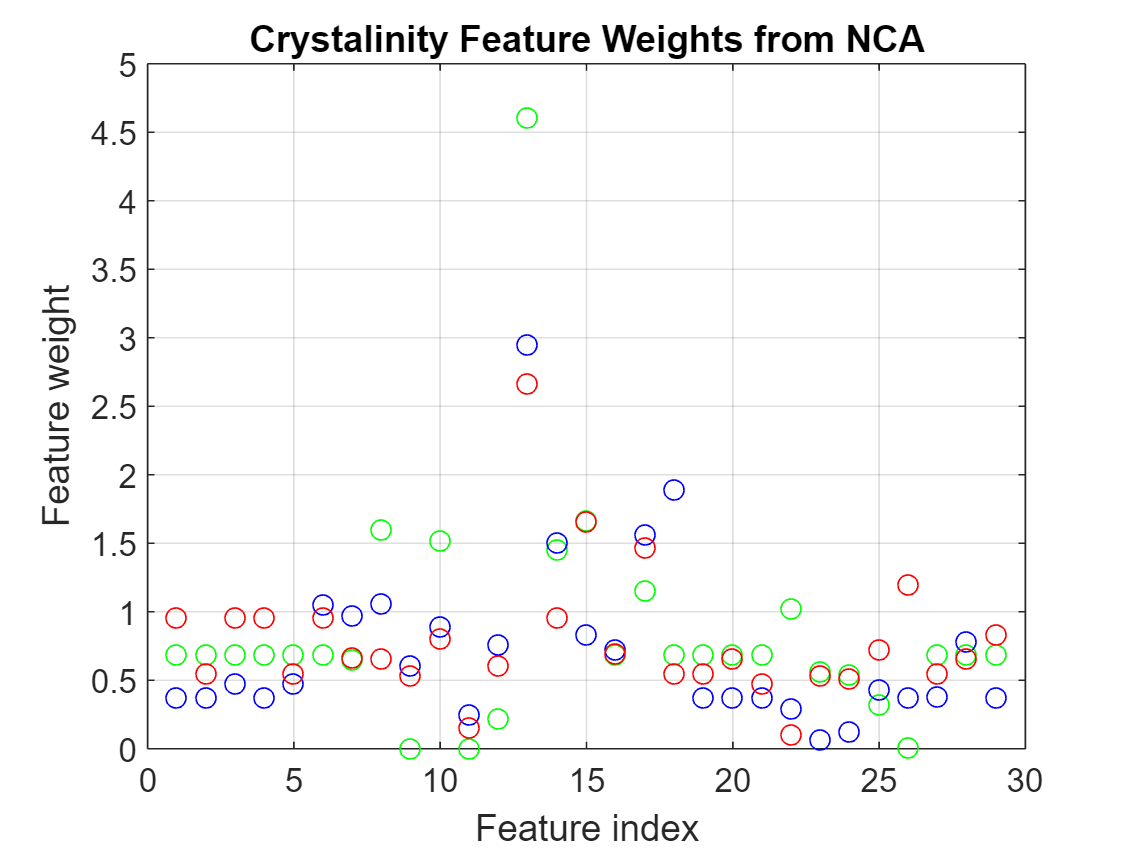

figure()
plot(nca_ac.FeatureWeights,'go')
grid on
hold on 
plot(nca_hc.FeatureWeights,'bo')
plot(nca_lc.FeatureWeights,'ro')
xlabel('Feature index')
ylabel('Feature weight')
title('Crystalinity Feature Weights from NCA')

weightsAC = nca_ac.FeatureWeights;
weightsLC = nca_lc.FeatureWeights;
weightsHC = nca_hc.FeatureWeights;
[~, wAC] = sort(weightsAC, 'descend');
[~, wLC] = sort(weightsLC, 'descend');
[~, wHC] = sort(weightsHC, 'descend');
% only taking 10 best features
fsNCA_ac = lablesE(1,wAC(1:10))

fsNCA_ac = 1×10 table
         lables13           lables18                  lables8                    lables10           lables14         lables23               lables32                 lables1                 lables2                   lables3      
    __________________    _____________    _____________________________    ___________________    ___________    ______________    ________________________    _________________    ________________________    ___________________

    {'WeightImpurity'}    {'impurityE'}    {'Contaminant_crystallinity'}    {'Contaminant_SCB'}    {'matrixE'}    {'impurityXc'}    {'MajorityPolymer_PET1'}    {'Matrix_family'}  

fsNCA_lc = lablesE(1,wLC(1:10))

fsNCA_lc = 1×10 table
         lables13           lables18          lables23              lables36                 lables1               lables3             lables4         lables14            lables6                   lables39         
    __________________    _____________    ______________    _______________________    _________________    ___________________    ______________    ___________    ____________________    _________________________

    {'WeightImpurity'}    {'impurityE'}    {'impurityXc'}    {'MajorityPolymer_PS1'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'matrixE'}    {'Matrix_viscosity'}    {'MinorityPolymer_

fsNCA_hc = lablesE(1,wHC(1:10))

fsNCA_hc = 1×10 table
         lables13                 lables28                lables23        lables14                 lables8                     lables6                  lables7                 lables10            lables18               lables38         
    __________________    _________________________    ______________    ___________    _____________________________    ____________________    ______________________    ___________________    _____________    _________________________

    {'WeightImpurity'}    {'MajorityPolymer_HDPE1'}    {'impurityXc'}    {'matrixE'}    {'Contaminant_crystallinity'}    {'Matrix_viscosity'}    {'Contaminant_fami


% first col; matrix fam 
[idxAC,scoresAC] = fsrftest(x_ac,y_ac);
[idxLC,scoresLC] = fsrftest(x_lc, y_lc);
[idxHC,scoresHC] = fsrftest(x_hc, y_hc);
fsFTEST_ac = lablesE(1,idxAC(1:10))

fsFTEST_ac = 1×10 table
         lables13              lables10             lables23         lables18              lables7                    lables9                  lables11                 lables33             lables14             lables34        
    __________________    ___________________    ______________    _____________    ______________________    ________________________    ___________________    _______________________    ___________    _______________________

    {'WeightImpurity'}    {'Contaminant_SCB'}    {'impurityXc'}    {'impurityE'}    {'Contaminant_family'}    {'Contaminant_topology'}    {'Contaminant_LCB'}    {'MajorityPolymer_PP

fsFTEST_hc = lablesE(1,idxHC(1:10))

fsFTEST_hc = 1×10 table
      lables22       lables14              lables28                   lables6                 lables3             lables5                lables9                lables23              lables7                    lables12         
    ____________    ___________    _________________________    ____________________    ___________________    ______________    ________________________    ______________    ______________________    _________________________

    {'matrixXc'}    {'matrixE'}    {'MajorityPolymer_HDPE1'}    {'Matrix_viscosity'}    {'Matrix_topology'}    {'Matrix_LCB'}    {'Contaminant_topology'}    {'impurityXc'}    {'Cont

fsFTEST_lc = lablesE(1,idxLC(1:10))

fsFTEST_lc = 1×10 table
         lables1               lables3             lables4              lables6            lables14        lables22         lables5                lables29                    lables31                     lables30         
    _________________    ___________________    ______________    ____________________    ___________    ____________    ______________    _________________________    _______________________    __________________________

    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_viscosity'}    {'matrixE'}    {'matrixXc'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_PA1'}


[imrMAC, scoresMAC] = fsrmrmr(x_ac,y_ac);
[imrMLC, scoresMLC] = fsrmrmr(x_lc,y_lc);
[imrMHC, scoresMHC] = fsrmrmr(x_hc,y_hc);
fsMRMR_ac = lablesE(1,imrMAC(1:10))

fsMRMR_ac = 1×10 table
         lables13                lables7                   lables35                    lables32                   lables33                   lables34                   lables36                 lables10               lables11                     lables8           
    __________________    ______________________    _______________________    ________________________    _______________________    _______________________    _______________________    ___________________    ___________________    _____________________________

    {'WeightImpurity'}    {'Contaminant_family'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PET1'}    {

fsMRMR_lc = lablesE(1,imrMLC(1:10))

fsMRMR_lc = 1×10 table
          lables6                lables13                lables35                 lables1            lables4              lables3               lables10                   lables30                lables5           lables23   
    ____________________    __________________    _______________________    _________________    ______________    ___________________    ___________________    __________________________    ______________    ______________

    {'Matrix_viscosity'}    {'WeightImpurity'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}    {'Matrix_SCB'}    {'Matrix_topology'}    {'Contaminant_SCB'}    {'MajorityPolymer_LLDPE1

fsMRMR_hc = lablesE(1,imrMHC(1:10))

fsMRMR_hc = 1×10 table
      lables22              lables12                     lables28                   lables6                  lables37               lables23             lables3                 lables35               lables5               lables7        
    ____________    _________________________    _________________________    ____________________    _______________________    ______________    ___________________    _______________________    ______________    ______________________

    {'matrixXc'}    {'Contaminant_viscosity'}    {'MajorityPolymer_HDPE1'}    {'Matrix_viscosity'}    {'MajorityPolymer_PS2'}    {'impurityXc'}    {'Matrix_topo


find(isinf(scoresAC)) 


ans =

  1×0 empty double row vector



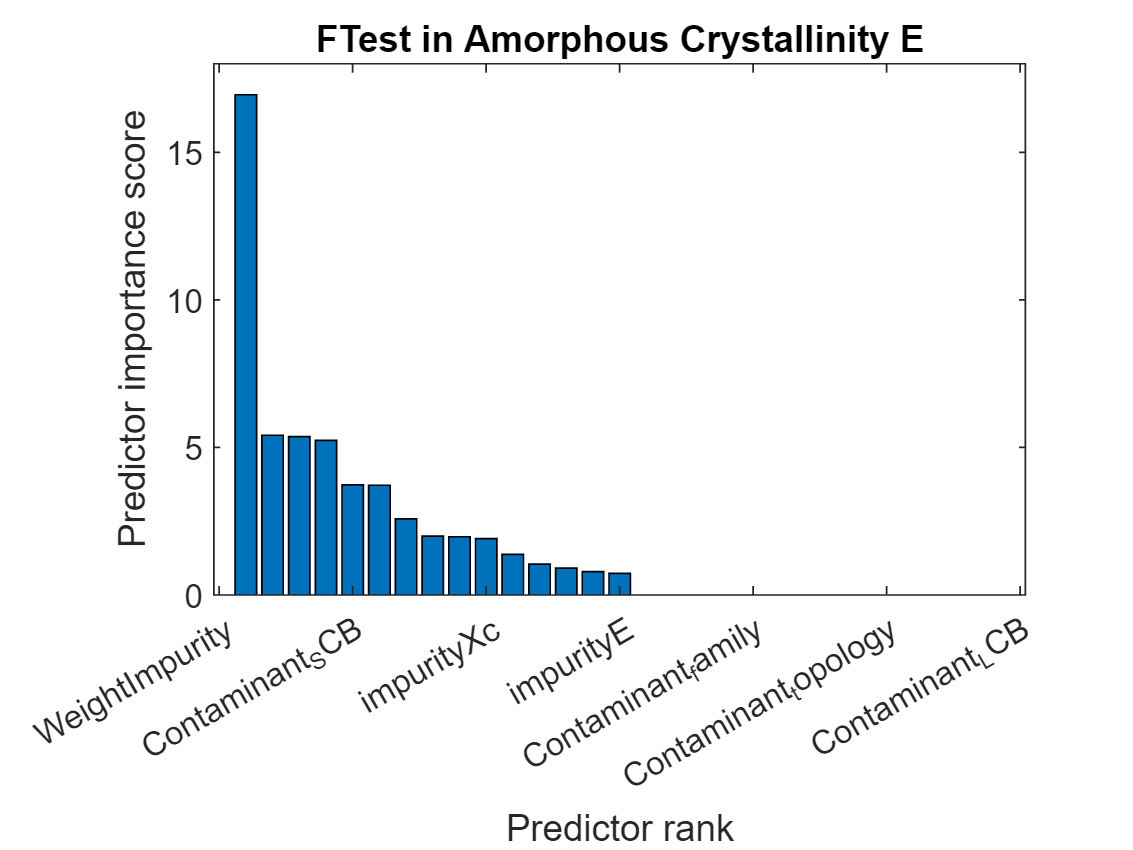

% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresAC(idxAC))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxAC)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Amorphous Crystallinity E')


find(isinf(scoresHC)) 


ans =

  1×0 empty double row vector



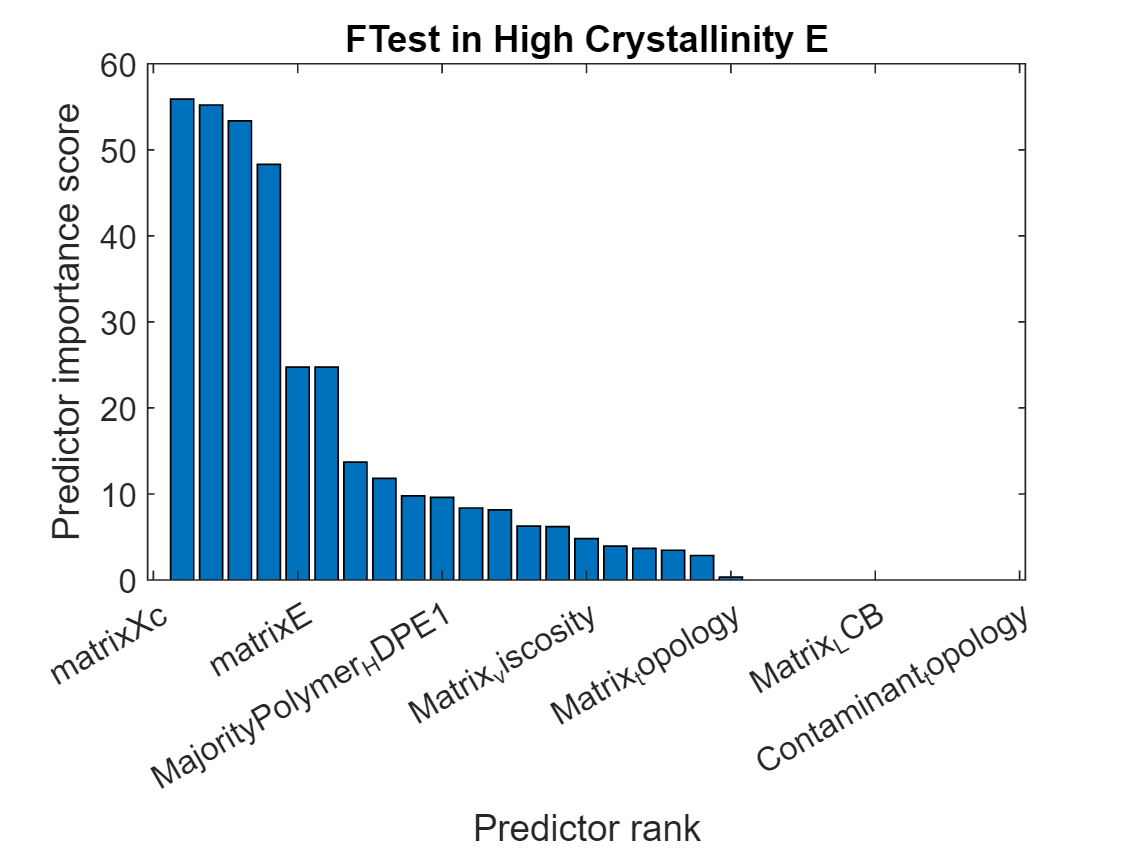

% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresHC(idxHC))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxHC)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in High Crystallinity E')


find(isinf(scoresLC)) 


ans =

  1×0 empty double row vector



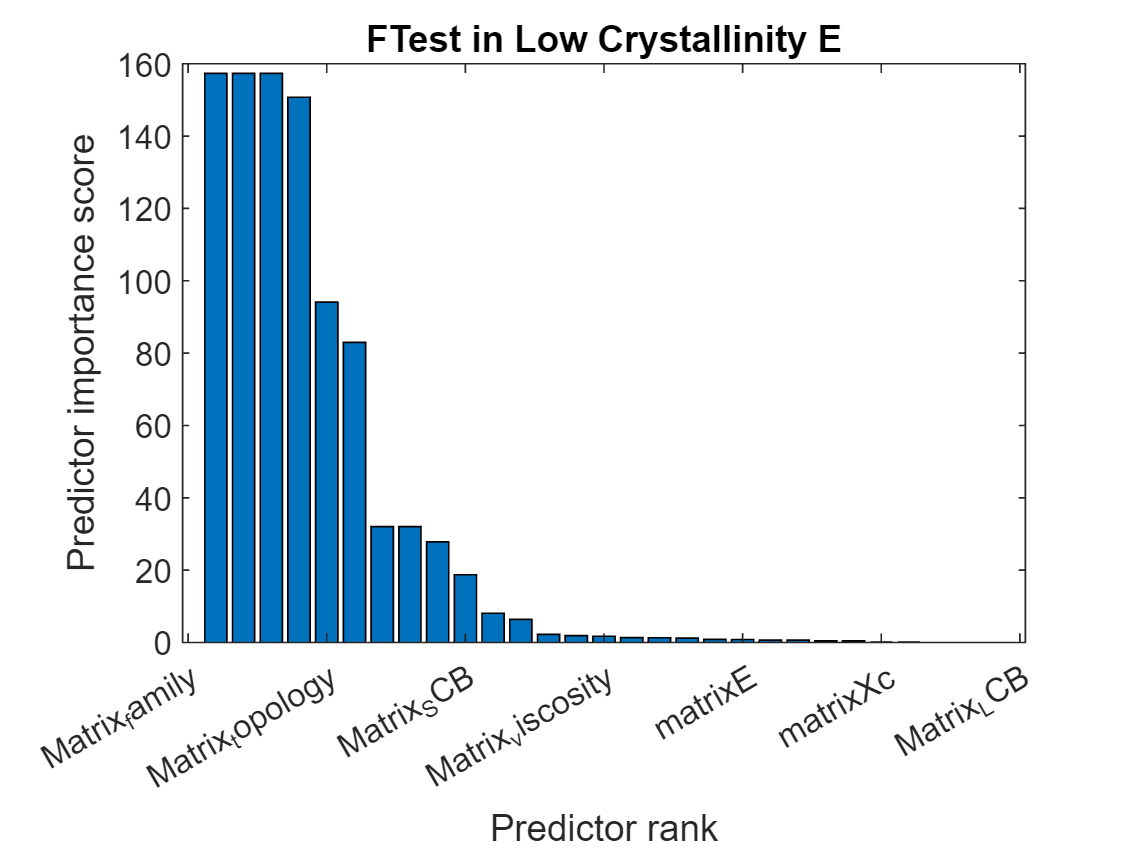

% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresLC(idxLC))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxLC)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Low Crystallinity E')

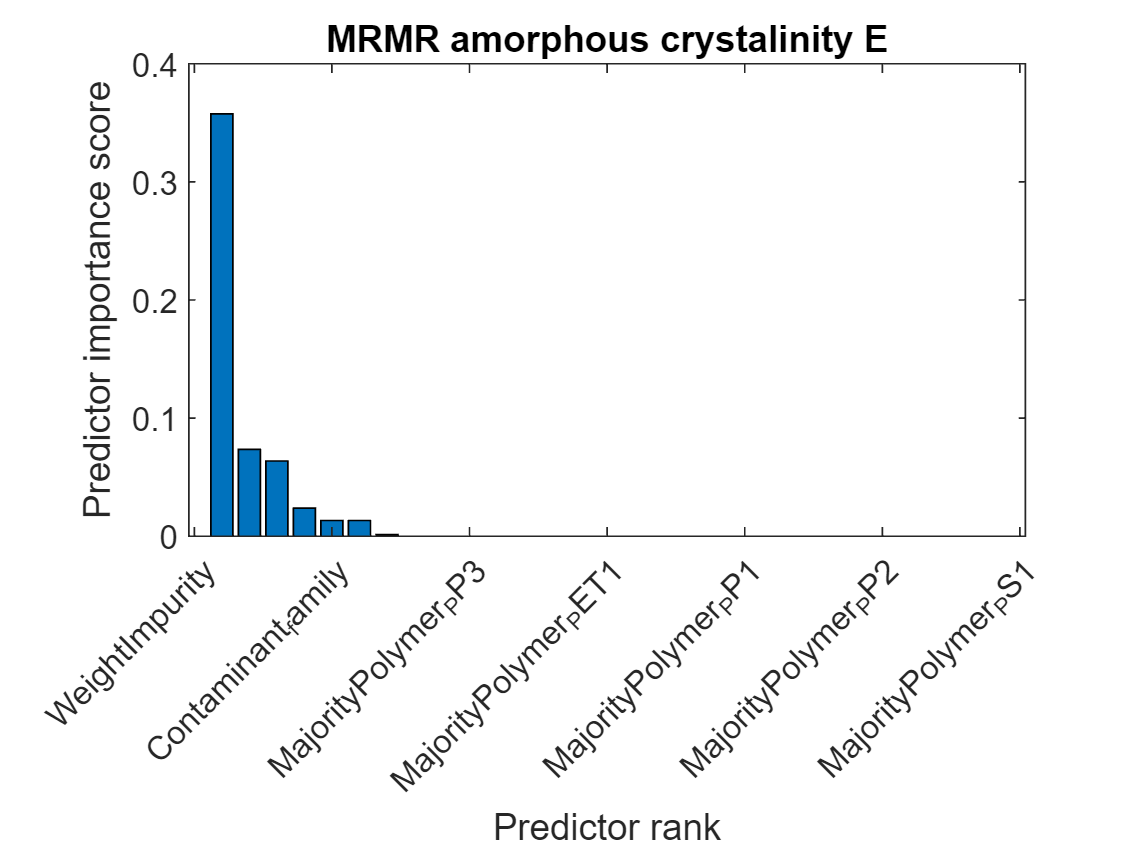


% mrmr tests
figure()
bar(scoresMAC(imrMAC))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR amorphous crystalinity E')
xticklabels(table2cell(fsMRMR_ac))
xtickangle(45)

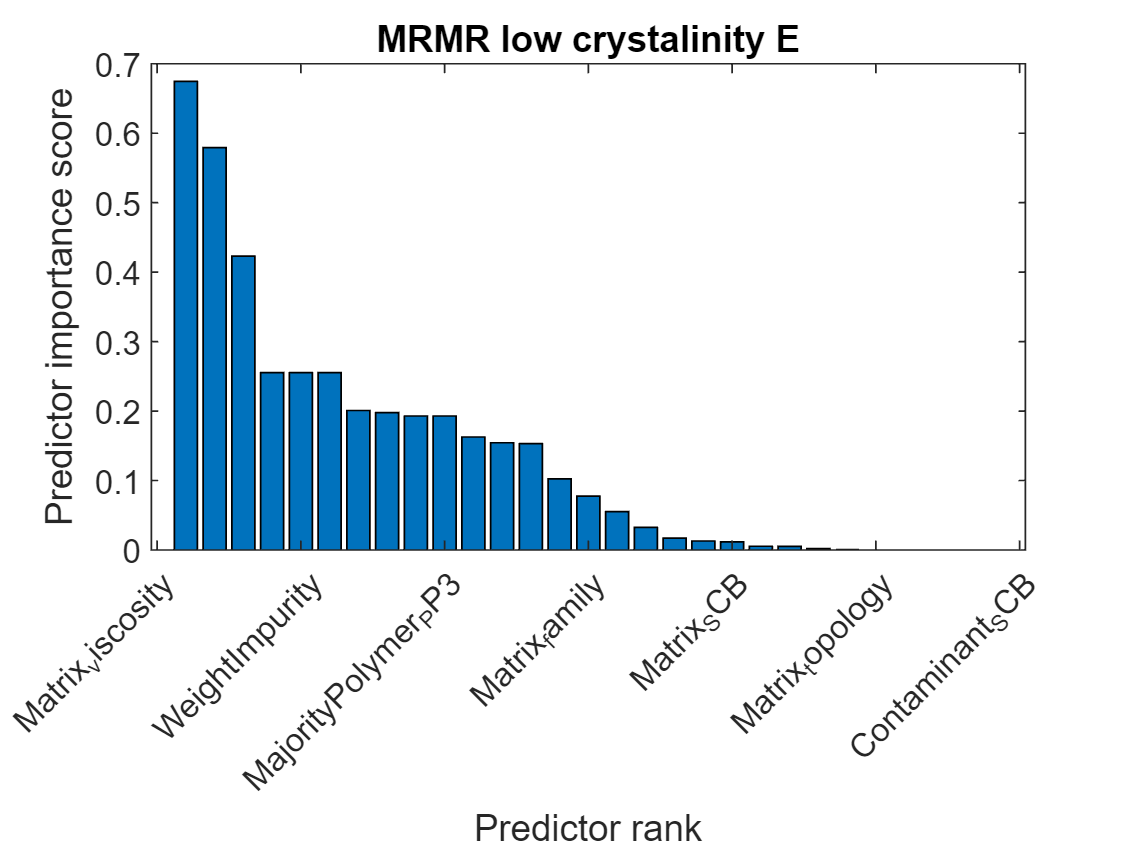


figure()
bar(scoresMLC(imrMLC))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR low crystalinity E')
xticklabels(table2cell(fsMRMR_lc))
xtickangle(45)

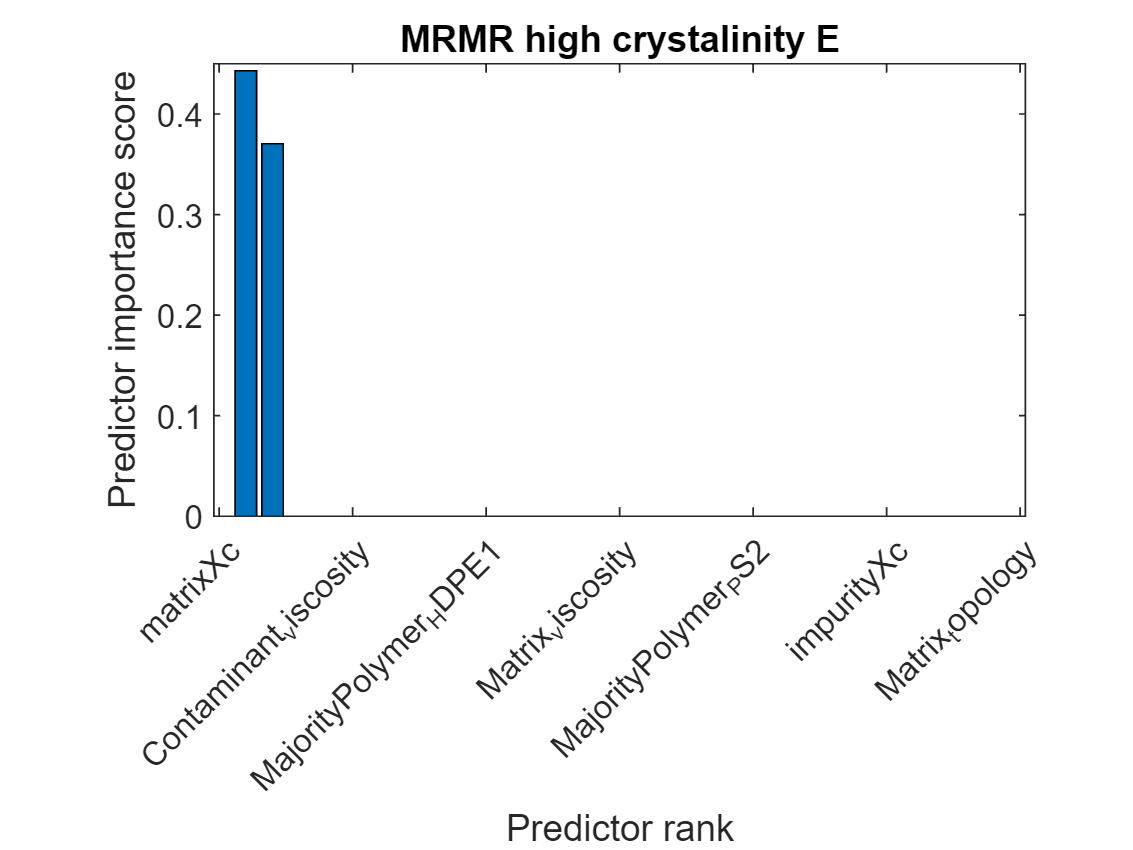


figure()
bar(scoresMHC(imrMHC))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR high crystalinity E')
xticklabels(table2cell(fsMRMR_hc))
xtickangle(45)

sc_ac=spearman_corr_n_best(x_ac, y_ac, 10)

sc_n = 10×1
     1
     2
     3
     4
     5
     6
    16
    18
    19
    20


sc_ac = 10×1
     1
     2
     3
     4
     5
     6
    16
    18
    19
    20


fsSC_ac = lablesE(1,sc_ac)

fsSC_ac = 1×10 table
         lables1                 lables2                   lables3             lables4           lables5              lables6             lables22              lables28                     lables29                      lables30         
    _________________    ________________________    ___________________    ______________    ______________    ____________________    ____________    _________________________    _________________________    __________________________

    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'matrixXc'}    {'MajorityPo

sc_lc=spearman_corr_n_best(x_lc, y_lc, 10)

sc_n = 10×1
     2
    18
    27
     1
     3
     4
     6
    14
    16
    20


sc_lc = 10×1
     2
    18
    27
     1
     3
     4
     6
    14
    16
    20


fsSC_lc = lablesE(1,sc_lc)

fsSC_lc = 1×10 table
            lables2                     lables28                    lables37                 lables1               lables3             lables4              lables6            lables14        lables22               lables30         
    ________________________    _________________________    _______________________    _________________    ___________________    ______________    ____________________    ___________    ____________    __________________________

    {'Matrix_crystallinity'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_PS2'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_viscosity'}    

sc_hc=spearman_corr_n_best(x_hc, y_hc, 10)

sc_n = 10×1
     1
     2
     4
    19
    20
    21
    26
    29
     6
    18


sc_hc = 10×1
     1
     2
     4
    19
    20
    21
    26
    29
     6
    18


fsSC_hc = lablesE(1,sc_hc)

fsSC_hc = 1×10 table
         lables1                 lables2                lables4                lables29                      lables30                    lables31                   lables36                    lables39                   lables6                   lables28         
    _________________    ________________________    ______________    _________________________    __________________________    _______________________    _______________________    _________________________    ____________________    _________________________

    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'MajorityPolymer_LDPE1'}    {'MajorityPo

rf_lc = table2array(PER(7,:))

rf_lc = 1×10
    12     3    14     5    13     9     2     0     6     8


fsPER_lc = lablesE(1,rf_idx)

fsPER_lc = 1×10 table
         lables13                 lables12              lables14        lables18         lables22              lables9                  lables1                lables35                  lables6                  lables45        
    __________________    _________________________    ___________    _____________    ____________    ________________________    _________________    _______________________    ____________________    _______________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE'}    {'impurityE'}    {'matrixXc'}    {'Contaminant_topology'}    {'Matrix_family'}    {'MajorityPolymer_PP3'}    {'Ma

rf_ac = table2array(PER(8,:))

rf_ac = 1×10
    12    14     9    11    16     6    13     8    29    15


fsPER_ac = lablesE(1,rf_idx)

fsPER_ac = 1×10 table
         lables13                 lables12              lables14        lables18         lables22              lables9                  lables1                lables35                  lables6                  lables45        
    __________________    _________________________    ___________    _____________    ____________    ________________________    _________________    _______________________    ____________________    _______________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE'}    {'impurityE'}    {'matrixXc'}    {'Contaminant_topology'}    {'Matrix_family'}    {'MajorityPolymer_PP3'}    {'Ma

rf_hc = table2array(PER(9,:))

rf_hc = 1×10
    15    13    12    14    17     9    28     5    10    16


fsPER_hc = lablesE(1,rf_idx)

fsPER_hc = 1×10 table
         lables13                 lables12              lables14        lables18         lables22              lables9                  lables1                lables35                  lables6                  lables45        
    __________________    _________________________    ___________    _____________    ____________    ________________________    _________________    _______________________    ____________________    _______________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE'}    {'impurityE'}    {'matrixXc'}    {'Contaminant_topology'}    {'Matrix_family'}    {'MajorityPolymer_PP3'}    {'Ma

features_ac = [table2array(fsNCA_ac),table2array(fsMRMR_ac),table2array(fsFTEST_ac), table2array(fsSC_ac), table2array(fsPER_ac)]

features_ac = 1×50 cell array
    {'WeightImpurity'}    {'impurityE'}    {'Contaminant_crystallinity'}    {'Contaminant_SCB'}    {'matrixE'}    {'impurityXc'}    {'MajorityPolymer_PET1'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'WeightImpurity'}    {'Contaminant_family'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PS1'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_crystallinity'}    {'WeightImpurity'}    {'Contaminant_SCB'}    {'impurityXc'}    {'impurityE'}    {'Contaminant_family'}    {'Contaminant_topology'}    {'Contaminant_LCB'}    {'MajorityPolymer_PP1'}    {'matrixE'}    {'MajorityPolymer_PP2'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'matrixXc'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'WeightImpur

features_lc = [table2array(fsNCA_lc),table2array(fsMRMR_lc),table2array(fsFTEST_lc), table2array(fsSC_lc), table2array(fsPER_lc)]

features_lc = 1×50 cell array
    {'WeightImpurity'}    {'impurityE'}    {'impurityXc'}    {'MajorityPolymer_PS1'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'matrixE'}    {'Matrix_viscosity'}    {'MinorityPolymer_LDPE1'}    {'Matrix_viscosity'}    {'WeightImpurity'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}    {'Matrix_SCB'}    {'Matrix_topology'}    {'Contaminant_SCB'}    {'MajorityPolymer_LLDPE1'}    {'Matrix_LCB'}    {'impurityXc'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_viscosity'}    {'matrixE'}    {'matrixXc'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_LLDPE1'}    {'Matrix_crystallinity'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_PS2'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_viscosity'}    {'matrixE'}    {'matrixXc'}    {'MajorityPolymer_LLDPE1'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE'}    {'impurity

features_hc = [table2array(fsNCA_hc),table2array(fsMRMR_hc),table2array(fsFTEST_hc), table2array(fsSC_hc), table2array(fsPER_hc)]

features_hc = 1×50 cell array
    {'WeightImpurity'}    {'MajorityPolymer_HDPE1'}    {'impurityXc'}    {'matrixE'}    {'Contaminant_crystallinity'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_SCB'}    {'impurityE'}    {'MinorityPolymer_HDPE1'}    {'matrixXc'}    {'Contaminant_viscosity'}    {'MajorityPolymer_HDPE1'}    {'Matrix_viscosity'}    {'MajorityPolymer_PS2'}    {'impurityXc'}    {'Matrix_topology'}    {'MajorityPolymer_PP3'}    {'Matrix_LCB'}    {'Contaminant_family'}    {'matrixXc'}    {'matrixE'}    {'MajorityPolymer_HDPE1'}    {'Matrix_viscosity'}    {'Matrix_topology'}    {'Matrix_LCB'}    {'Contaminant_topology'}    {'impurityXc'}    {'Contaminant_family'}    {'Contaminant_viscosity'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PS1'}    {'MinorityPolymer_LDPE1'}    {'Matrix_viscosity'}    {'MajorityPolymer_HDPE1'}    {'Wei

## topology


Lt = readtable('data_reduced_linear_topo.csv');
Bt = readtable('data_reduced_branched_topo.csv');


% because of ârtition the first col(matrix family) will not be relevant 
lt =  table2array(lt(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
bt  =  table2array(bt(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
% separate cols
x_lt= [lt(:,1:17), lt(:,19:end)];
y_lt = lt(:,18);
x_bt= [bt(:,1:17), bt(:,19:end)];
y_bt = bt(:,18);


% use best lamdba from past CVwith whole dataset?
nca_lt = fsrnca(x_lt, y_lt, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda);


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  9.393163e+01 |   2.000000e-01 |
|            2 |  9.393163e+01 |   2.000000e-01 |
|            3 |  9.393163e+01 |   2.000000e-01 |
|            4 |  9.393163e+01 |   2.000000e-01 |
|            5 |  9.393163e+01 |   2.000000e-01 |
|            6 |  9.393163e+01 |   2.000000e-01 |
|            7 |  9.393163e+01 |   2.000000e-01 |
|            8 |  9.393163e+01 |   2.000000e-01 |
|            9 |  9.393163e+01 |   2.000000e-01 |
|           10 |  9.393163e+01 |   2.000000e-01 |
|           11 |  9.393163e+01 |   2.000000e-01 |
|           12 |  9.393163e+01 |   2.000000e-01 |
|           13 |  9.393163e+01 |   2.000000e-01 |
|           14 |  9.393163e+01 |   2.000000e-01 |
|           15 |

nca_bt = fsrnca(x_bt, y_bt, 'Verbose', 2, 'Standardize', true, 'Solver', 'sgd', 'Lambda', bestlambda)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.011011e+02 |   2.000000e-01 |
|            2 |  8.805319e+01 |   4.000000e-01 |
|            3 |  6.562861e+01 |   8.000000e-01 |
|            4 |  6.562861e+01 |   8.000000e-01 |
|            5 |  6.562861e+01 |   8.000000e-01 |
|            6 |  6.562861e+01 |   8.000000e-01 |
|            7 |  6.562861e+01 |   8.000000e-01 |
|            8 |  6.562861e+01 |   8.000000e-01 |
|            9 |  6.562861e+01 |   8.000000e-01 |
|           10 |  6.562861e+01 |   8.000000e-01 |
|           11 |  6.562861e+01 |   8.000000e-01 |
|           12 |  6.562861e+01 |   8.000000e-01 |
|           13 |  6.562861e+01 |   8.000000e-01 |
|           14 |  6.562861e+01 |   8.000000e-01 |
|           15 |

nca_bt =   FeatureSelectionNCARegression
          NumObservations: 133
          ModelParameters: [1×1 struct]
                   Lambda: 3.2092e-04
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: [29×1 double]
                    Sigma: [29×1 double]
                        X: [133×29 double]
                        Y: [133×1 double]
                        W: [133×1 double]


  Properties, Methods


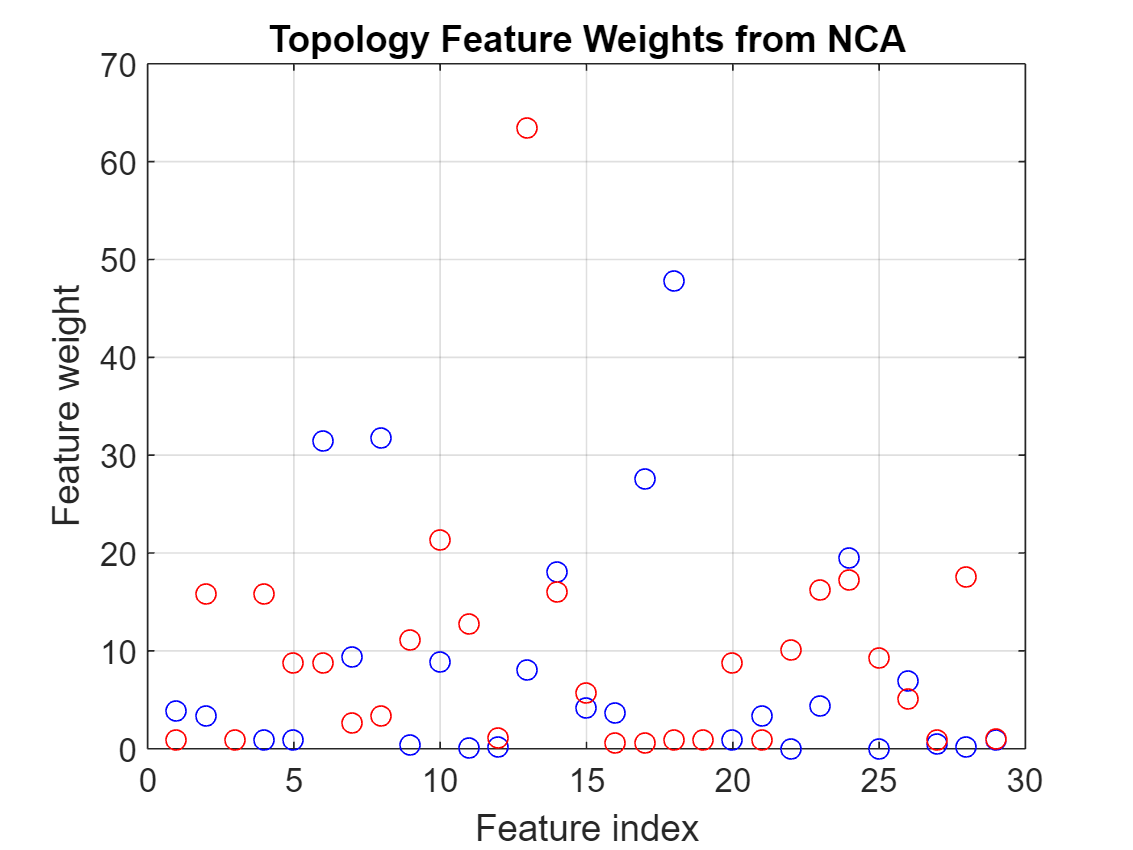

figure()
plot(nca_lt.FeatureWeights,'bo')
grid on
hold on 
plot(nca_bt.FeatureWeights,'ro')
hold off
xlabel('Feature index')
ylabel('Feature weight')
title('Topology Feature Weights from NCA')

weightslt = nca_lt.FeatureWeights;
weightsbt = nca_bt.FeatureWeights;
[~, wlt] = sort(weightslt, 'descend');
[~, wbt] = sort(weightsbt, 'descend');

% only taking 10 best features
fsNCA_lt = lablesE(1,wlt(1:10))

fsNCA_lt = 1×10 table
            lables28                        lables8                     lables6              lables23              lables34             lables14             lables7                 lables10               lables13                lables36        
    _________________________    _____________________________    ____________________    ______________    _______________________    ___________    ______________________    ___________________    __________________    _______________________

    {'MajorityPolymer_HDPE1'}    {'Contaminant_crystallinity'}    {'Matrix_viscosity'}    {'impurityXc'}    {'MajorityPolymer_PP2'}    {'matrixE'} 

fsNCA_bt = lablesE(1,wbt(1:10))

fsNCA_bt = 1×10 table
         lables13              lables10                  lables38                    lables34                   lables33             lables14              lables2                lables4             lables11                  lables9         
    __________________    ___________________    _________________________    _______________________    _______________________    ___________    ________________________    ______________    ___________________    ________________________

    {'WeightImpurity'}    {'Contaminant_SCB'}    {'MinorityPolymer_HDPE1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP1'}    {'matrixE'}    {'Matrix

% first col; matrix fam 
[idxlt,scoreslt] = fsrftest(x_lt,y_lt);
[idxbt,scoresbt] = fsrftest(x_bt, y_bt);

fsFTEST_lt = lablesE(1,idxlt(1:10))

fsFTEST_lt = 1×10 table
          lables6            lables14        lables22              lables2                  lables1                 lables28               lables18              lables36                   lables37                    lables12         
    ____________________    ___________    ____________    ________________________    _________________    _________________________    _____________    _______________________    _______________________    _________________________

    {'Matrix_viscosity'}    {'matrixE'}    {'matrixXc'}    {'Matrix_crystallinity'}    {'Matrix_family'}    {'MajorityPolymer_HDPE1'}    {'impurityE'}    {'MajorityPol

fsFTEST_bt = lablesE(1,idxbt(1:10))

fsFTEST_bt = 1×10 table
            lables2                lables4         lables14        lables22              lables29                lables5              lables6                    lables30                lables23         lables18   
    ________________________    ______________    ___________    ____________    _________________________    ______________    ____________________    __________________________    ______________    _____________

    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'matrixE'}    {'matrixXc'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'MajorityPolymer_LLDPE1'}    {'impurityXc'}    {'impur


[imrMlt, scoresMlt] = fsrmrmr(x_lt,y_lt);
[imrMbt, scoresMbt] = fsrmrmr(x_bt,y_bt);

fsMRMR_lt = lablesE(1,imrMlt(1:10))

fsMRMR_lt = 1×10 table
      lables22           lables13                lables36                    lables28                     lables2                  lables1            lables23              lables37             lables14             lables31        
    ____________    __________________    _______________________    _________________________    ________________________    _________________    ______________    _______________________    ___________    _______________________

    {'matrixXc'}    {'WeightImpurity'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_HDPE1'}    {'Matrix_crystallinity'}    {'Matrix_family'}    {'impurityXc'}    {'Majorit

fsMRMR_bt = lablesE(1,imrMbt(1:10))

fsMRMR_bt = 1×10 table
      lables22              lables9                  lables13                 lables2                lables4                lables29                lables5                 lables30                lables23        lables14  
    ____________    ________________________    __________________    ________________________    ______________    _________________________    ______________    __________________________    ______________    ___________

    {'matrixXc'}    {'Contaminant_topology'}    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'} 


find(isinf(scoreslt)) 


ans =

  1×0 empty double row vector



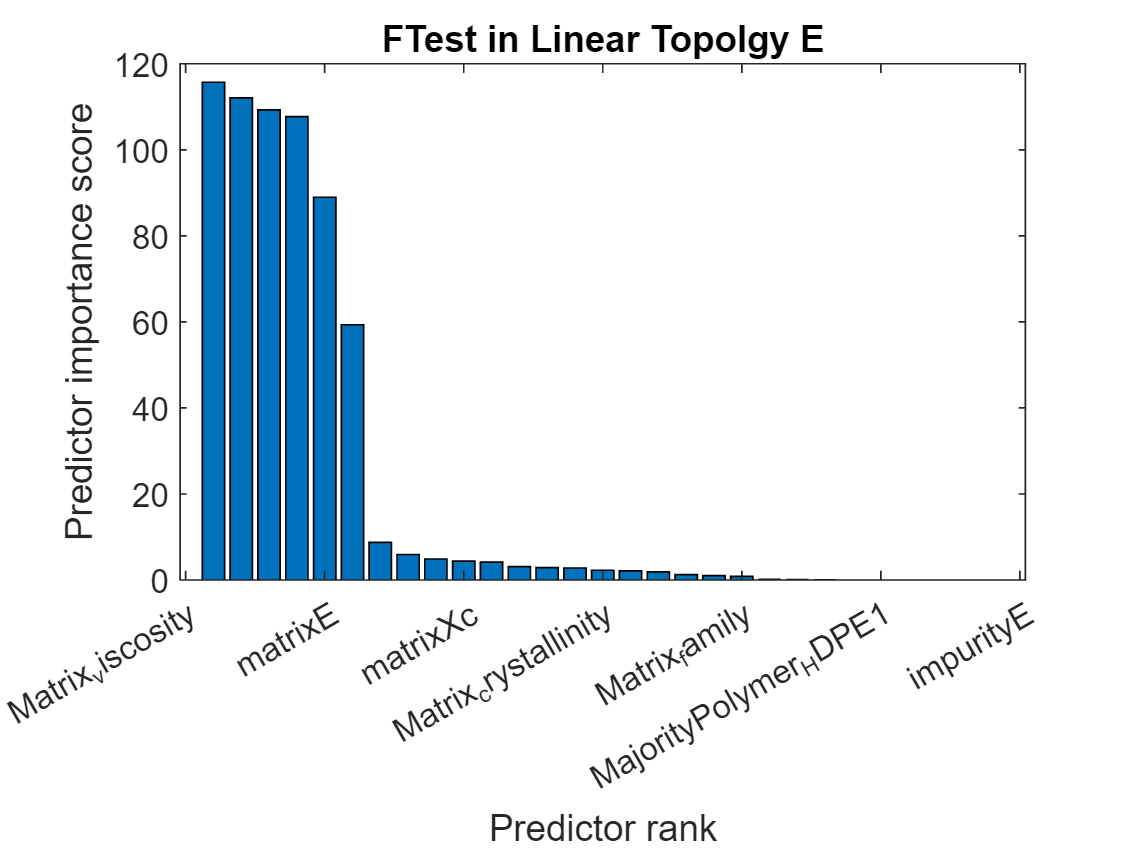

% no neg pvalues, meaning null hypothesis??
figure()
bar(scoreslt(idxlt))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxlt)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Linear Topolgy E')



find(isinf(scoresbt)) 


ans =

  1×0 empty double row vector



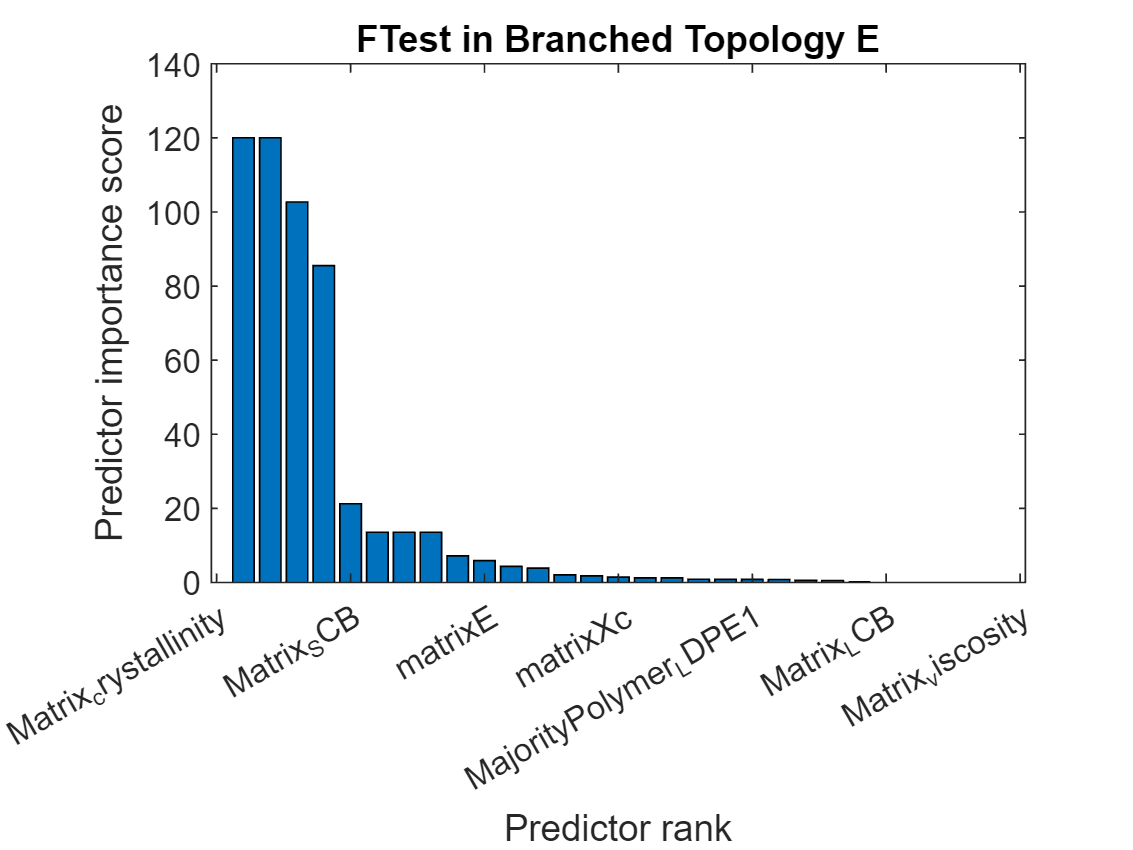

% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresbt(idxbt))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxbt)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Branched Topology E')

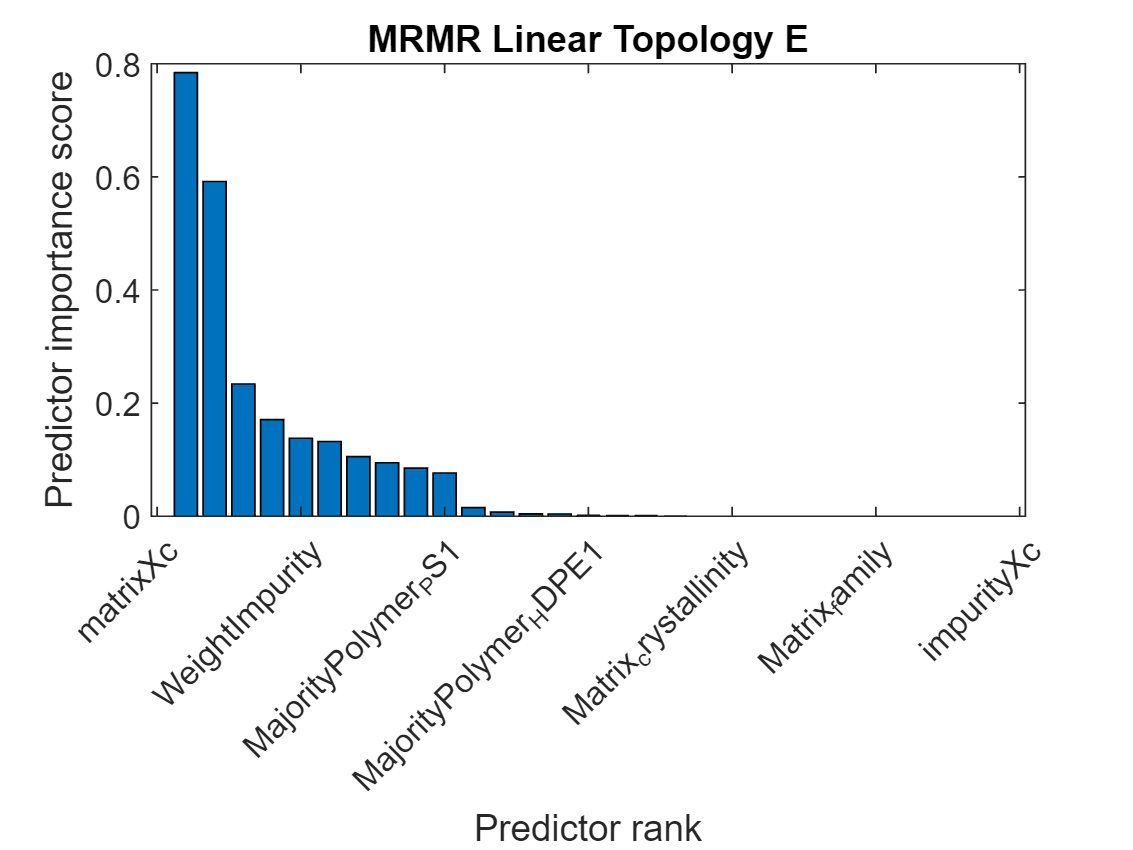


% mrmr tests
figure()
bar(scoresMlt(imrMlt))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR Linear Topology E')
xticklabels(table2cell(fsMRMR_lt))
xtickangle(45)

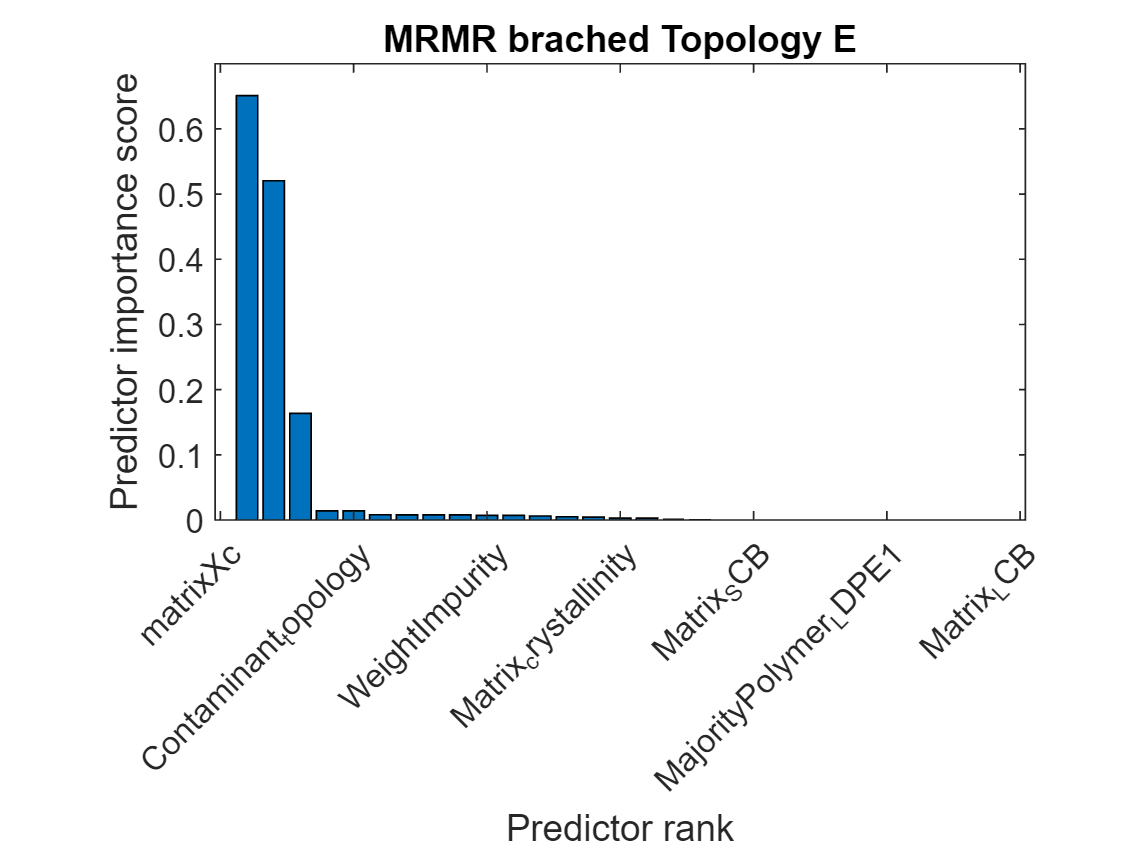


figure()
bar(scoresMbt(imrMbt))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR brached Topology E')
xticklabels(table2cell(fsMRMR_bt))
xtickangle(45)

sc_lt=spearman_corr_n_best(x_lt, y_lt, 10)

sc_n = 10×1
     3
     4
     5
    19
    20
    29
    16
    14
     2
     1


sc_lt = 10×1
     3
     4
     5
    19
    20
    29
    16
    14
     2
     1


fsSC_lt = lablesE(1,sc_lt)

fsSC_lt = 1×10 table
          lables3             lables4           lables5                lables29                      lables30                     lables39               lables22       lables14              lables2                  lables1     
    ___________________    ______________    ______________    _________________________    __________________________    _________________________    ____________    ___________    ________________________    _________________

    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MinorityPolymer_LDPE1'}    {'matrixXc'}    {'matrixE'}    

sc_bt=spearman_corr_n_best(x_bt, y_bt, 10)

sc_n = 10×1
     1
     3
    18
    21
    27
     2
     4
    16
    14
     5


sc_bt = 10×1
     1
     3
    18
    21
    27
     2
     4
    16
    14
     5


fsSC_bt = lablesE(1,sc_bt)

fsSC_bt = 1×10 table
         lables1               lables3                  lables28                    lables31                   lables37                    lables2                lables4          lables22       lables14         lables5    
    _________________    ___________________    _________________________    _______________________    _______________________    ________________________    ______________    ____________    ___________    ______________

    {'Matrix_family'}    {'Matrix_topology'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PS2'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'matrixXc'}   

rf_lt = table2array(PER(5,:))

rf_lt = 1×10
    13    12    15    14     1    25    17     8    16    11


fsPER_lt = lablesE(1,rf_lt)

fsPER_lt = 1×10 table
         lables13                 lables12               lables18        lables14           lables1                lables35               lables23                  lables8                 lables22           lables11      
    __________________    _________________________    _____________    ___________    _________________    _______________________    ______________    _____________________________    ____________    ___________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'impurityE'}    {'matrixE'}    {'Matrix_family'}    {'MajorityPolymer_PP3'}    {'impurityXc'}    {'Contaminant_crystallinity'}    {'matri

rf_bt = table2array(PER(6,:))

rf_bt = 1×10
    12    14     3     1    16    15    22    13    35     8


fsPER_bt = lablesE(1,rf_bt)

fsPER_bt = 1×10 table
            lables12              lables14            lables3               lables1           lables22        lables18               lables32                 lables13                lables45                       lables8           
    _________________________    ___________    ___________________    _________________    ____________    _____________    ________________________    __________________    _______________________    _____________________________

    {'Contaminant_viscosity'}    {'matrixE'}    {'Matrix_topology'}    {'Matrix_family'}    {'matrixXc'}    {'impurityE'}    {'MajorityPolymer_PET1'}    {'WeightImpurity'}  

features_lt = [table2array(fsNCA_lt),table2array(fsMRMR_lt),table2array(fsFTEST_lt), table2array(fsSC_lt), table2array(fsPER_lt)]

features_lt = 1×50 cell array
    {'MajorityPolymer_HDPE1'}    {'Contaminant_crystallinity'}    {'Matrix_viscosity'}    {'impurityXc'}    {'MajorityPolymer_PP2'}    {'matrixE'}    {'Contaminant_family'}    {'Contaminant_SCB'}    {'WeightImpurity'}    {'MajorityPolymer_PS1'}    {'matrixXc'}    {'WeightImpurity'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_HDPE1'}    {'Matrix_crystallinity'}    {'Matrix_family'}    {'impurityXc'}    {'MajorityPolymer_PS2'}    {'matrixE'}    {'MajorityPolymer_PA1'}    {'Matrix_viscosity'}    {'matrixE'}    {'matrixXc'}    {'Matrix_crystallinity'}    {'Matrix_family'}    {'MajorityPolymer_HDPE1'}    {'impurityE'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'Contaminant_viscosity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MinorityPolymer_LDPE1'}    {'matrixXc'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_family'}    {'WeightImpurity'}    {'Contamin

features_bt = [table2array(fsNCA_bt),table2array(fsMRMR_bt),table2array(fsFTEST_bt), table2array(fsSC_lt), table2array(fsPER_bt)]

features_bt = 1×50 cell array
    {'WeightImpurity'}    {'Contaminant_SCB'}    {'MinorityPolymer_HDPE1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP1'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'Contaminant_LCB'}    {'Contaminant_topology'}    {'matrixXc'}    {'Contaminant_topology'}    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'}    {'impurityXc'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'matrixE'}    {'matrixXc'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'MajorityPolymer_LLDPE1'}    {'impurityXc'}    {'impurityE'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MinorityPolymer_LDPE1'}    {'matrixXc'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_family'}    {'Contaminant_viscosity'}    {'matrixE'}    {'Matrix_topology'} 

## BORDA COUNT FS

idea that feature #1 has 10 points and the ones not in the ranking 


% create matrix of (m,2) 
testNames = {'NCA_whole', 'MRMR_whole', 'FTEST_whole', 'SC_whole','PER_whole','NCA_p', 'MRMR_p', 'FTEST_p', 'SC_p', 'PER_p','NCA_np', 'MRMR_np', 'FTEST_np', 'SC_np','PER_np', 'NCA_lt', 'MRMR_lt', 'FTEST_lt', 'SC_lt','PER_lt','NCA_bt', 'MRMR_bt', 'FTEST_bt', 'SC_bt','PER_bt','NCA_lc', 'MRMR_lc', 'FTEST_lc' , 'SC_lc','PER_lc','NCA_ac', 'MRMR_ac', 'FTEST_ac', 'SC_ac','PER_ac','NCA_hc', 'MRMR_hc', 'FTEST_hc', 'SC_hc', 'PER_hc'}

testNames = 1×40 cell array
    {'NCA_whole'}    {'MRMR_whole'}    {'FTEST_whole'}    {'SC_whole'}    {'PER_whole'}    {'NCA_p'}    {'MRMR_p'}    {'FTEST_p'}    {'SC_p'}    {'PER_p'}    {'NCA_np'}    {'MRMR_np'}    {'FTEST_np'}    {'SC_np'}    {'PER_np'}    {'NCA_lt'}    {'MRMR_lt'}    {'FTEST_lt'}    {'SC_lt'}    {'PER_lt'}    {'NCA_bt'}    {'MRMR_bt'}    {'FTEST_bt'}    {'SC_bt'}    {'PER_bt'}    {'NCA_lc'}    {'MRMR_lc'}    {'FTEST_lc'}    {'SC_lc'}    {'PER_lc'}    {'NCA_ac'}    {'MRMR_ac'}    {'FTEST_ac'}    {'SC_ac'}    {'PER_ac'}    {'NCA_hc'}    {'MRMR_hc'}    {'FTEST_hc'}    {'SC_hc'}    {'PER_hc'}


borda = array2table(zeros(length(testNames), width(lablesE)+1));
%rows cannot be saved in a file with the row names so add extr col to keep test names
col_names = ['testName', table2cell(lablesE)]

col_names = 1×38 cell array
    {'testName'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'impurityE'}    {'matrixXc'}    {'impurityXc'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'MinorityPolymer_PA1'}    {'MinorityPolymer_PET1'}    {'MinorityPolymer_PP1'}    {'MinorityPolymer_PP2'}    {'MinorityPolymer_PP3'}    {'MinorityPolymer_PS1'}    {'MinorityPolymer_PS2'}


borda.Properties.VariableNames = col_names;
borda.testName = testNames'

borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

% borda.Properties.RowNames =testNames
fs_total = [features, features_p, features_np, features_lt, features_bt, features_lc, features_ac, features_hc]

fs_total = 1×400 cell array
    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'impurityXc'}    {'MajorityPolymer_HDPE1'}    {'Contaminant_SCB'}    {'Matrix_SCB'}    {'Matrix_viscosity'}    {'Contaminant_crystallinity'}    {'impurityE'}    {'matrixE'}    {'matrixE'}    {'WeightImpurity'}    {'MajorityPolymer_PS2'}    {'MajorityPolymer_LDPE1'}    {'Matrix_SCB'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'MajorityPolymer_HDPE1'}    {'matrixE'}    {'matrixXc'}    {'Matrix_viscosity'}    {'Matrix_family'}    {'Matrix_SCB'}    {'Matrix_topology'}    {'Matrix_crystallinity'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'}    {'matrixE'}    {'Matrix_SCB'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'matrixXc'}    {'Matrix_LCB'}    {'MajorityPolymer_PA1'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrix

% NESTED LOOP outer: evry test of parition (rows) INNER: 10 ranks found
for j=1:length(testNames)
    for i =1: 10
        %  sets of 10 given test  and the feature looking for + 1 because 1
        %  col is testnames 
        idx = (10 * (j-1) + i)
        idx = fs_total(idx) 
        % if i =1 then its the highest rank and add 10 points
        % j here corresponds to the test, thus row
        borda(j, idx) = {11-i}
    end 
end

idx = 1

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 2

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 3

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 4

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 5

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 6

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 7

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 8

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 9

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 10

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 11

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 12

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 13

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 14

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 15

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 16

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 17

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 18

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 19

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 20

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 21

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 22

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 23

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 24

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 25

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 26

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 27

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 28

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 29

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 30

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 31

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 32

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 33

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 34

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 35

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 36

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 37

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 38

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 39

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 40

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 41

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 42

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 43

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 44

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 45

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 46

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 47

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 48

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 49

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 50

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 51

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 52

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 53

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 54

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 55

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 56

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 57

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 58

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 59

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 60

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 61

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 62

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 63

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 64

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 65

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 66

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 67

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 68

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 69

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 70

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 71

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 72

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 73

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 74

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 75

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 76

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 77

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 78

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 79

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 80

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 81

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 82

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 83

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 84

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 85

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 86

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 87

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 88

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 89

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 90

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 91

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 92

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 93

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 94

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 95

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 96

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 97

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 98

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 99

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 100

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 101

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 102

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 103

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 104

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 105

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 106

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 107

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 108

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 109

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 110

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 111

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 112

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 113

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 114

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 115

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 116

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 117

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 118

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 119

idx = 1×1 cell array
    {'MajorityPolymer_PET1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 120

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 121

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 122

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 123

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 124

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 125

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 126

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 127

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 128

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 129

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 130

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 131

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 132

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 133

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 134

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 135

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 136

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 137

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 138

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 139

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 140

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 141

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 142

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 143

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 144

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 145

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 146

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 147

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 148

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 149

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 150

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 151

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 152

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 153

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 154

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 155

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 156

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 157

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 158

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 159

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 160

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 161

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 162

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 163

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 164

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 165

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 166

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 167

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 168

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 169

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 170

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 171

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 172

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 173

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 174

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 175

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 176

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 177

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 178

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 179

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 180

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 181

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 182

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 183

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 184

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 185

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 186

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 187

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 188

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 189

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 190

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 191

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 192

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 193

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 194

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 195

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 196

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 197

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 198

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 199

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 200

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 201

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 202

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 203

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 204

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 205

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 206

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 207

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 208

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 209

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 210

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 211

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 212

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 213

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 214

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 215

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 216

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 217

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 218

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 219

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 220

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 221

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 222

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 223

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 224

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 225

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 226

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 227

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 228

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 229

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 230

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 231

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 232

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 233

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 234

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 235

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 236

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 237

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 238

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 239

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 240

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 241

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 242

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 243

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 244

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 245

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 246

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 247

idx = 1×1 cell array
    {'MajorityPolymer_PET1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 248

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 249

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 250

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 251

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 252

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 253

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 254

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 255

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 256

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 257

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 258

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 259

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 260

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 261

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 262

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 263

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 264

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 265

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 266

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 267

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 268

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 269

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 270

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 271

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 272

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 273

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 274

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 275

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 276

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 277

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 278

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 279

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 280

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 281

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 282

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 283

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 284

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 285

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 286

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 287

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 288

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 289

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 290

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 291

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 292

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 293

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 294

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 295

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 296

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 297

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 298

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 299

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 300

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 301

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 302

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 303

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 304

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 305

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 306

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 307

idx = 1×1 cell array
    {'MajorityPolymer_PET1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 308

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 309

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 310

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 311

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 312

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 313

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 314

idx = 1×1 cell array
    {'MajorityPolymer_PET1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 315

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 316

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 317

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 318

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 319

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 320

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 321

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 322

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 323

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 324

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 325

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 326

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 327

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 328

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 329

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 330

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 331

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 332

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 333

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 334

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 335

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 336

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 337

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 338

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 339

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 340

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 341

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 342

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 343

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 344

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 345

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 346

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 347

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 348

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 349

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 350

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 351

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 352

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 353

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 354

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 355

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 356

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 357

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 358

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 359

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 360

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 361

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 362

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 363

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 364

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 365

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 366

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 367

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 368

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 369

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 370

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 371

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 372

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 373

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 374

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 375

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 376

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 377

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 378

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 379

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 380

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 381

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 382

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 383

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 384

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 385

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 386

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 387

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 388

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 389

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 390

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 391

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 392

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 393

idx = 1×1 cell array
    {'matrixE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 394

idx = 1×1 cell array
    {'impurityE'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 395

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 396

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 397

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 398

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 399

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

idx = 400

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×38 table
       testName        Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    M

labels = 1×38 cell array
    {'testName'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'impurityE'}    {'matrixXc'}    {'impurityXc'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'MinorityPolymer_PA1'}    {'MinorityPolymer_PET1'}    {'MinorityPolymer_PP1'}    {'MinorityPolymer_PP2'}    {'MinorityPolymer_PP3'}    {'MinorityPolymer_PS1'}    {'MinorityPolymer_PS2'}


bordaName = 'borda_count_filtering.csv';
writetable(borda, bordaName, 'Delimiter', ',');

check = readtable('borda_count_filtering.csv');

totals = table2array(sum(borda))

totals = 1×37
   158   112   110   126    71   123    40    38    50    51    14    91   215   195   122   162    79    91    63    46    18    17    24    22    48    46    30    13    16     0


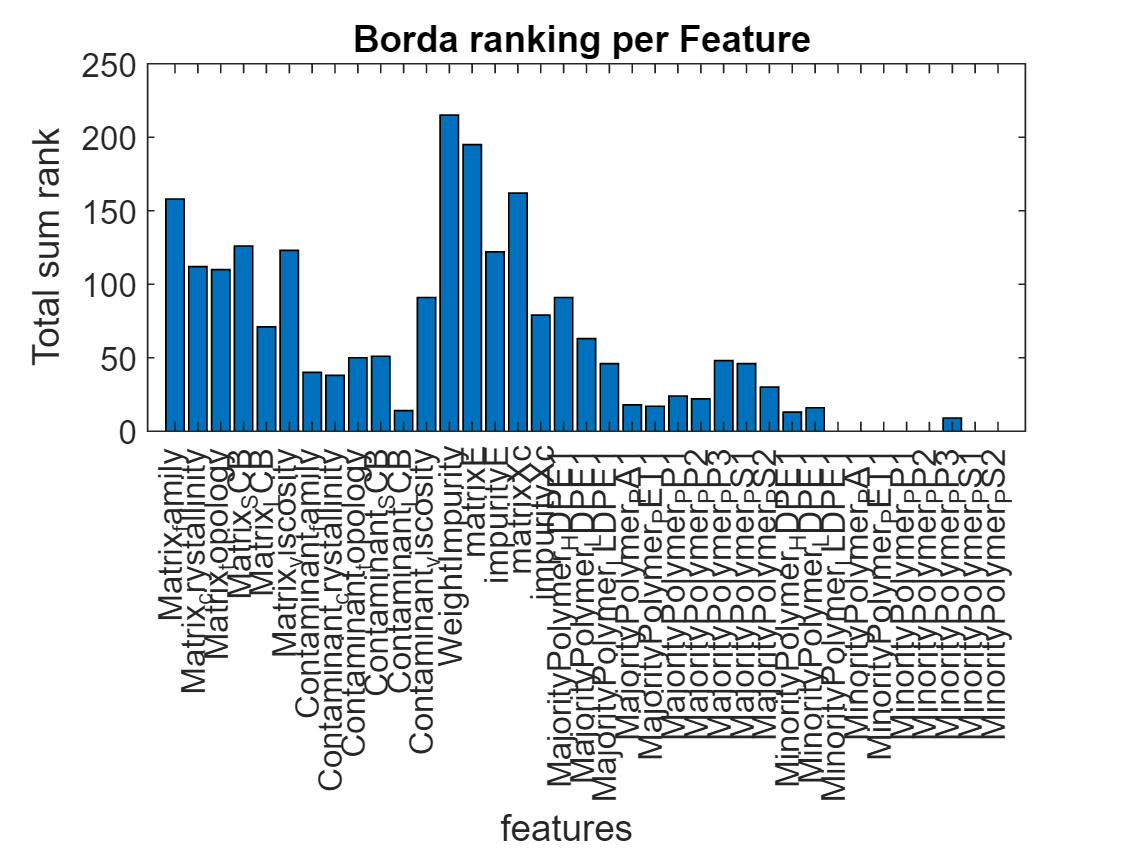


figure();
bar(1:numel(lablesE),totals)
% set(gca, 'XTickLabel', lablesE)
xticks(1:numel(lablesE))
xticklabels(table2array(lablesE))
title('Borda ranking per Feature ')
xlabel('features    ')
ylabel('Total sum rank')

[results, indexes]=sort(totals, 'descend')

results = 1×37
   215   195   162   158   126   123   122   112   110    91    91    79    71    63    51    50    48    46    46    40    38    30    24    22    18    17    16    14    13     9


indexes = 1×37
    13    14    16     1     4     6    15     2     3    12    18    17     5    19    10     9    25    20    26     7     8    27    23    24    21    22    29    11    28    35


% TRYING NCA FOR GUASSIAN KERNEL
% 
% XTrain = array2table(Xe);
% [Transformer,newXTrain] = genrfeatures(XTrain,Ye,47,TargetLearner="gaussian-svm")
% 
%  % the engineered features are stored after the five original features in the Transformer object.
% featIndex = 6:8; 
% describe(Transformer,featIndex)
% Y_tbl = array2table(Ye)
% % plotmatrix(newXTrain{:,featIndex})
% 
% % newY = transform(Transformer,Y_tbl, 47)


% Mdl = fitrsvm(newTrainTbl,"MPG",KernelFunction="gaussian", ...
%     KernelScale="auto");
% testMSE = loss(Mdl,newY,"MPG")
nca = get_method(1,borda)

nca = 8×37 table
                 Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

function sc_n = spearman_corr_n_best(x, y, n)
    sc = corr(x,y ,'Type', 'Spearman');
    [sorted_corr, sorted_idx] = sort(abs(sc), 'descend');
    sc_n = sorted_idx(1:n)
end

%NCA 1, MRMR 2 FTEST 3 SC 4 RF 5 ;partutions are kept ordered given their 5
%methods applied. There will be 8 results per method (1+7 partitions) 
function result = get_method(m,B)
    [r, c] = size(B); idx = zeros(1,8); idx(1,1) = m;
    for i =2: 8
         idx(i)= idx(i-1) + 5;  
    end
    result = B(idx, :);
end

function result = get_partiton(p, B)
    start_idx = (p-1)*5 + 1;
    % i =1 ; 1 to 5 
    result = B(start_idx : start_idx + 4, :);
end